# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
kristen_file_path = "/home/kristenangell/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);
json_text_plot = fileread(david_file_path + "plot_config.json");
plot_config = jsondecode(json_text_plot);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;
BIN_WIDTH = sim_config.TestSettings.Configurations.bin_width;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();
values = zeros(0,0);
raw_data = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

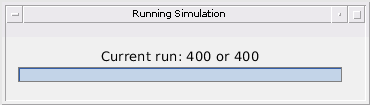

target_velocity = 10

estimated_ranges =   101.1956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.1903       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.4874       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.0775  101.7835       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   101.0000  101.2667  101.5334  101.8000  102.0667  102.3334  102.6001  102.8667  103.1334  103.4001


estimated_velocities =    -8.0136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9283       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0086       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7355   -8.0120       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     2
     1
     2
     2
     3
     3
     2


false_positives =      0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.1956
    0.0763
    0.0459
    0.0165
    0.0377
    0.0553
    0.1151
    0.1443
    0.0965
    0.0607


percent_error_velocities =     0.0136
    0.0717
    0.0086
    0.0120
    0.0116
    0.0057
    0.0054
    0.0002
    0.0020
    0.0282


target_velocity = -29

estimated_ranges =    59.9348       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.7441       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   57.7740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.7724       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    60.0000   58.9666   57.9333   56.8999   55.8665   54.8332   53.7998   52.7664   51.7331   50.6997


estimated_velocities =    30.9002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9316       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9311       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9372       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     31    31    31    31    31    31    31    31    31    31


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.0652
    0.2225
    0.1592
    0.1275
    0.0590
    0.1929
    0.1911
    0.1189
    0.0901
    0.1403


percent_error_velocities =     0.0998
    0.0684
    0.0689
    0.0628
    0.0576
    0.1362
    0.0499
    0.0573
    0.0979
    0.2160


target_velocity = -11

estimated_ranges =    97.8999       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.4778       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.0528       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.6256       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    98.0000   97.5667   97.1333   96.7000   96.2666   95.8333   95.3999   94.9666   94.5332   94.0999


estimated_velocities =    12.9872       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9917       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9929       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9959       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     13    13    13    13    13    13    13    13    13    13


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives =      0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges =     0.1001
    0.0888
    0.0805
    0.0743
    0.0644
    0.0558
    0.0462
    0.0345
    0.0288
    0.0160


percent_error_velocities =     0.0128
    0.0083
    0.0071
    0.0041
    0.0158
    0.0105
    0.0097
    0.0198
    0.0215
    0.0250


target_velocity = 11

estimated_ranges =   120.1475       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.4088       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.2702  120.6980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.0312  120.9661       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   120.0000  120.3000  120.6000  120.9000  121.2000  121.5000  121.8001  122.1001  122.4001  122.7001


estimated_velocities =    -8.9665       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9985       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.4134   -9.0179       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.2554   -8.9998       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      1
     1
     2
     2
     1
     1
     1
     1
     1
     1


false_positives =      0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.1475
    0.1088
    0.0979
    0.0661
    0.0195
    0.0142
    0.0232
    0.0439
    0.0507
    0.1784


percent_error_velocities =     0.0335
    0.0015
    0.0179
    0.0002
    0.0015
    0.0093
    0.0092
    0.0516
    0.0541
    0.0144


target_velocity = -18

estimated_ranges =   153.0691   22.9782       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.6950   22.2455       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.4717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9895       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =    23.0000   22.3333   21.6666   20.9999   20.3332   19.6666   18.9999   18.3332   17.6665   16.9998


estimated_velocities =    28.8066   19.9273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.3057   19.9834       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9736       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9578       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     20    20    20    20    20    20    20    20    20    20


detected =      1     1     1     1     1     1     1     1     1     1


col_detection =      2
     2
     1
     1
     1
     1
     2
     1
     1
     1


false_positives =      1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges =     0.0218
    0.0878
    0.1950
    0.0104
    0.0900
    0.1761
    0.0081
    0.1005
    0.1598
    0.0165


percent_error_velocities =     0.0727
    0.0166
    0.0264
    0.0422
    0.0198
    0.0504
    0.0238
    0.0155
    0.0870
    0.0854


target_velocity = -35

estimated_ranges =   125.8948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  124.5852       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.2970  123.3353       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.1718       NaN       NaN       NaN       NaN       NaN       NaN       N

actual_ranges =   126.0000  124.7666  123.5333  122.2999  121.0665  119.8331  118.5998  117.3664  116.1330  114.8996


estimated_velocities =    36.9201       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9112       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.6021   36.7540       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9295       NaN       NaN       NaN       NaN       NaN       NaN    

actual_velocities =     37    37    37    37    37    37    37    37    37    37


detected =      1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1052
    0.1814
    0.1979
    0.1281
    0.2200
    0.1026
    0.1527
    0.2304
    0.0905
    0.1603


percent_error_velocities = 10×1
    0.0799
    0.0888
    0.2460
    0.0705
    0.0375
    0.1927
    0.0731
    0.0903
    0.0952
    0.0680


target_velocity = 30

estimated_ranges = 10×30
  130.1310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.0849       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.9373       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  171.3089  132.9684       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  130.0000  130.9334  131.8667  132.8001  133.7335  134.6668  135.6002  136.5335  137.4669  138.4003


estimated_velocities = 10×30
  -27.9331       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.7694       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9606       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.6087  -27.8732       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     3
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1310
    0.1516
    0.0706
    0.1684
    0.0887
    0.2289
    0.0948
    0.1363
    0.0639
    0.1352


percent_error_velocities = 10×1
    0.0669
    0.2306
    0.0394
    0.1268
    0.0712
    0.0034
    0.1498
    0.0807
    0.0812
    0.0695


target_velocity = 13

estimated_ranges = 10×30
    7.8946   59.9892       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.4047       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  151.9897   60.8379       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.1065       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   60.0000   60.3667   60.7334   61.1000   61.4667   61.8334   62.2001   62.5667   62.9334   63.3001


estimated_velocities = 10×30
    4.5979  -10.9220       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9730       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.6785  -10.9093       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9716       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0108
    0.0380
    0.1046
    0.0065
    0.1272
    0.0085
    0.0891
    0.0265
    0.0416
    0.0990


percent_error_velocities = 10×1
    0.0780
    0.0270
    0.0907
    0.0284
    0.0330
    0.0575
    0.0292
    0.0668
    0.0286
    0.0986


target_velocity = -34

estimated_ranges = 10×30
   69.8717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.6049       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  168.3566   67.4740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.1906       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   70.0000   68.8000   67.5999   66.3999   65.1998   63.9998   62.7998   61.5997   60.3997   59.1997


estimated_velocities = 10×30
   35.7750       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9248       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.5721   35.8799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8630       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1283
    0.1950
    0.1260
    0.2093
    0.1398
    0.1427
    0.1945
    0.1257
    0.2061
    0.1357


percent_error_velocities = 10×1
    0.2250
    0.0752
    0.1201
    0.1370
    0.0781
    0.2301
    0.0755
    0.1284
    0.1232
    0.0800


target_velocity = -5

estimated_ranges = 10×30
   45.9695       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.6354       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.5727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  197.6697   45.2224       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   46.0000   45.7667   45.5333   45.3000   45.0666   44.8333   44.6000   44.3666   44.1333   43.8999


estimated_velocities = 10×30
    6.9985       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9853       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9996       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.1884    7.0022       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0305
    0.1313
    0.0394
    0.0776
    0.0190
    0.0084
    0.0834
    0.0806
    0.0218
    0.1247


percent_error_velocities = 10×1
    0.0015
    0.0147
    0.0004
    0.0022
    0.0287
    0.0039
    0.0068
    0.0037
    0.0015
    0.0009


target_velocity = -26

estimated_ranges = 10×30
  110.9129       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.8975       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.0252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.0485       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  111.0000  110.0666  109.1333  108.1999  107.2665  106.3332  105.3998  104.4665  103.5331  102.5997


estimated_velocities = 10×30
   27.9712       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8963       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.9195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8353       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0871
    0.1691
    0.1081
    0.1514
    0.0133
    0.1379
    0.0767
    0.1711
    0.0918
    0.1274


percent_error_velocities = 10×1
    0.0288
    0.1037
    0.0805
    0.1647
    0.0262
    0.0816
    0.1147
    0.0319
    0.2024
    0.0535


target_velocity = 9

estimated_ranges = 10×30
  135.1333       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.1594       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.7773  135.5188       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  180.7231  135.9011       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  135.2333  135.4667  135.7000  135.9334  136.1667  136.4000  136.6334  136.8667  137.1001


estimated_velocities = 10×30
   -6.9852       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.2258   -7.0054       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.6910   -6.9906       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1333
    0.0739
    0.0521
    0.2011
    0.0105
    0.0673
    0.1713
    0.0096
    0.1249
    0.0594


percent_error_velocities = 10×1
    0.0148
    0.0001
    0.0054
    0.0094
    0.0010
    0.0043
    0.0289
    0.0050
    0.0050
    0.0182


target_velocity = 18

estimated_ranges = 10×30
   85.1514       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.5216       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  153.1828   86.1079       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   86.7062       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   85.0000   85.5334   86.0667   86.6001   87.1334   87.6668   88.2001   88.7335   89.2668   89.8002


estimated_velocities = 10×30
  -15.9566       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9508       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.7643  -15.9772       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9619       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1514
    0.0117
    0.0412
    0.1062
    0.1409
    0.0074
    0.0536
    0.1194
    0.1157
    0.0067


percent_error_velocities = 10×1
    0.0434
    0.0492
    0.0228
    0.0381
    0.0795
    0.0368
    0.0285
    0.0380
    0.1858
    0.0196


target_velocity = 4

estimated_ranges = 10×30
   29.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.1701       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.1317       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.4965   30.3187       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   30.0000   30.0667   30.1333   30.2000   30.2667   30.3333   30.4000   30.4667   30.5334   30.6000


estimated_velocities = 10×30
   -2.0144       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0111       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0146       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.0160   -2.0134       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0282
    0.1034
    0.0017
    0.1187
    0.0073
    0.0524
    0.0163
    0.0611
    0.0470
    0.0814


percent_error_velocities = 10×1
    0.0144
    0.0111
    0.0146
    0.0134
    0.0164
    0.0067
    0.0163
    0.0042
    0.0164
    0.0033


target_velocity = -8

estimated_ranges = 10×30
   68.9433       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.6947       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.1968       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.9302       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   69.0000   68.6667   68.3333   68.0000   67.6666   67.3333   66.9999   66.6666   66.3332   65.9999


estimated_velocities = 10×30
    9.9733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9663       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9778       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0567
    0.0280
    0.1365
    0.0697
    0.0101
    0.1042
    0.0469
    0.0107
    0.1280
    0.0546


percent_error_velocities = 10×1
    0.0267
    0.0337
    0.0304
    0.0222
    0.0423
    0.0804
    0.0284
    0.0579
    0.0560
    0.0260


target_velocity = 28

estimated_ranges = 10×30
   61.1954       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.0452       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.8900       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  143.2093   63.7382       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   61.8667   62.7334   63.6001   64.4668   65.3335   66.2002   67.0669   67.9336   68.8002


estimated_velocities = 10×30
  -25.9716       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9751       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.4829  -25.9756       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1954
    0.1785
    0.1566
    0.1381
    0.1180
    0.0960
    0.0713
    0.0432
    0.0184
    0.0043


percent_error_velocities = 10×1
    0.0284
    0.0249
    0.0266
    0.0244
    0.0345
    0.0424
    0.0250
    0.0246
    0.0286
    0.0357


target_velocity = 34

estimated_ranges = 10×30
  106.1468       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.5482  107.2153       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  199.5644  108.2900       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.3559       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  106.0000  107.0667  108.1334  109.2001  110.2668  111.3335  112.4002  113.4669  114.5336  115.6003


estimated_velocities = 10×30
  -31.9547       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -41.8183  -31.7325       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.8597  -31.9623       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.7222       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     2
     3
     3
     2
     3
     2


false_positives = 10×1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1468
    0.1486
    0.1566
    0.1558
    0.1754
    0.0303
    0.1949
    0.0484
    0.2087
    0.0574


percent_error_velocities = 10×1
    0.0453
    0.2675
    0.0377
    0.2778
    0.0494
    0.0773
    0.0586
    0.0736
    0.0480
    0.0403


target_velocity = 5

estimated_ranges = 10×30
  137.1114       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.0374       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  171.8315  137.2276       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.4269       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  137.0000  137.1000  137.2000  137.3000  137.4000  137.5000  137.6000  137.7000  137.8000  137.9000


estimated_velocities = 10×30
   -2.9655       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9775       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.7922   -3.0285       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0104       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1114
    0.0626
    0.0276
    0.1269
    0.1190
    0.0246
    0.0772
    0.1799
    0.0410
    0.0284


percent_error_velocities = 10×1
    0.0345
    0.0225
    0.0285
    0.0104
    0.0092
    0.0037
    0.0111
    0.0570
    0.0323
    0.0034


target_velocity = -29

estimated_ranges = 10×30
  130.8767       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.9320       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  128.7143       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  127.7121       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  131.0000  129.9666  128.9333  127.8999  126.8665  125.8332  124.7998  123.7664  122.7331  121.6997


estimated_velocities = 10×30
   30.9664       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.8723       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9571       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1233
    0.0346
    0.2190
    0.1878
    0.1218
    0.0699
    0.1597
    0.2002
    0.1308
    0.0687


percent_error_velocities = 10×1
    0.0336
    0.0514
    0.1277
    0.0429
    0.0477
    0.1215
    0.2655
    0.0547
    0.0555
    0.0601


target_velocity = 6

estimated_ranges = 10×30
   83.7216  126.1111       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.2698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.1587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.3192       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  126.1333  126.2667  126.4000  126.5334  126.6667  126.8000  126.9334  127.0667  127.2000


estimated_velocities = 10×30
  -27.4609   -3.9422       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9802       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9957       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1111
    0.1365
    0.1079
    0.0808
    0.0609
    0.0573
    0.0290
    0.0076
    0.0084
    0.0198


percent_error_velocities = 10×1
    0.0578
    0.0276
    0.0198
    0.0043
    0.0184
    0.0297
    0.0147
    0.0222
    0.0202
    0.0171


target_velocity = 25

estimated_ranges = 10×30
   41.1254   40.1630       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.8795       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.5733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.4386       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   40.0000   40.7667   41.5334   42.3001   43.0668   43.8335   44.6001   45.3668   46.1335   46.9002


estimated_velocities = 10×30
   21.7291  -22.9177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9498       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9157       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.8953       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     3
     2
     2
     3
     2


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1630
    0.1128
    0.0400
    0.1386
    0.0875
    0.0739
    0.1383
    0.0583
    0.1285
    0.1212


percent_error_velocities = 10×1
    0.0823
    0.0502
    0.0843
    0.1047
    0.0654
    0.1645
    0.0584
    0.0535
    0.1744
    0.0473


target_velocity = 27

estimated_ranges = 10×30
   49.8770  117.1276       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.0030       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.8574       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.5243       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  117.8334  118.6667  119.5001  120.3334  121.1668  122.0002  122.8335  123.6669  124.5002


estimated_velocities = 10×30
  -42.8169  -24.9587       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.8965       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.8973       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1276
    0.1696
    0.1907
    0.0242
    0.0298
    0.0698
    0.1097
    0.1523
    0.2081
    0.0283


percent_error_velocities = 10×1
    0.0413
    0.0454
    0.1035
    0.1027
    0.0377
    0.0323
    0.0451
    0.0597
    0.0517
    0.0312


target_velocity = -10

estimated_ranges = 10×30
  123.6144  111.9131       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.4229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.2715       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.7975       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  112.0000  111.6000  111.2000  110.8000  110.3999  109.9999  109.5999  109.1999  108.7999  108.3999


estimated_velocities = 10×30
  -33.6643   11.9676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9836       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9689       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9602       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     1
     2
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0869
    0.1771
    0.0715
    0.0024
    0.0613
    0.1120
    0.1534
    0.0182
    0.0011
    0.0494


percent_error_velocities = 10×1
    0.0324
    0.0164
    0.0311
    0.0398
    0.0203
    0.0138
    0.0382
    0.0637
    0.0268
    0.0128


target_velocity = 2

estimated_ranges = 10×30
   36.9752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9755  218.0238       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.3623   36.9748       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9759       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    37    37    37    37    37    37    37    37    37    37


estimated_velocities = 10×30
   -0.1758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1758   -9.3012       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.7337   -0.1758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1758       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     3
     2
     3


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0248
    0.0245
    0.0252
    0.0241
    0.0240
    0.0244
    0.0256
    0.0240
    0.0239
    0.0236


percent_error_velocities = 10×1
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758


target_velocity = 10

estimated_ranges = 10×30
  212.8780   20.9761       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.2640       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.5862       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.8684  106.4070       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   21.0000   21.2667   21.5334   21.8000   22.0667   22.3334   22.6001   22.8667   23.1334   23.4001


estimated_velocities = 10×30
  -10.1451   -7.9998       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0103       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0089       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0022  -18.4138       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     3
     2
     3
     2
     2


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0239
    0.0026
    0.0529
    0.0683
    0.1224
    0.1262
    0.0674
    0.0373
    0.0105
    0.0135


percent_error_velocities = 10×1
    0.0002
    0.0103
    0.0089
    0.0022
    0.0067
    0.0198
    0.0143
    0.0234
    0.0040
    0.0097


target_velocity = 26

estimated_ranges = 10×30
   99.1356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.8429       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.6813       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.5705       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   99.8000  100.6001  101.4001  102.2001  103.0001  103.8002  104.6002  105.4002  106.2002


estimated_velocities = 10×30
  -23.9546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8954       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9589       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8786       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1356
    0.0429
    0.0813
    0.1704
    0.0456
    0.1489
    0.0691
    0.0977
    0.1730
    0.0358


percent_error_velocities = 10×1
    0.0454
    0.1046
    0.0411
    0.1214
    0.0394
    0.0303
    0.1612
    0.0489
    0.0766
    0.0436


target_velocity = -19

estimated_ranges = 10×30
   71.9436       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.2278       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   70.4808       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.7748       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   72.0000   71.3000   70.6000   69.8999   69.1999   68.4999   67.7999   67.0998   66.3998   65.6998


estimated_velocities = 10×30
   20.9827       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9933       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9888       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9707       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0564
    0.0722
    0.1191
    0.1251
    0.1759
    0.2001
    0.1098
    0.0760
    0.0455
    0.0023


percent_error_velocities = 10×1
    0.0173
    0.0067
    0.0112
    0.0293
    0.0109
    0.0687
    0.1796
    0.2081
    0.0994
    0.0118


target_velocity = 11

estimated_ranges = 10×30
   62.9719       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.3418       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.7649       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.0236       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   63.0000   63.3000   63.6000   63.9000   64.2000   64.5000   64.8001   65.1001   65.4001   65.7001


estimated_velocities = 10×30
   -8.9444       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.8870       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9933       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9898       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0281
    0.0418
    0.1649
    0.1236
    0.0771
    0.0640
    0.0435
    0.0018
    0.0404
    0.0194


percent_error_velocities = 10×1
    0.0556
    0.1130
    0.0067
    0.0102
    0.0111
    0.0061
    0.0025
    0.0003
    0.0042
    0.0556


target_velocity = 22

estimated_ranges = 10×30
   86.1603       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.0570   86.7291       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   87.4002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.4411   88.1838       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   86.0000   86.6667   87.3334   88.0001   88.6668   89.3334   90.0001   90.6668   91.3335   92.0002


estimated_velocities = 10×30
  -19.9493       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.8969  -19.8355       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.0367  -19.9952       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     2
     3
     3
     3
     3


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1603
    0.0624
    0.0668
    0.1837
    0.0218
    0.0669
    0.1621
    0.0425
    0.0727
    0.1445


percent_error_velocities = 10×1
    0.0507
    0.1645
    0.0023
    0.0048
    0.0790
    0.0272
    0.0081
    0.0057
    0.0301
    0.0492


target_velocity = -4

estimated_ranges = 10×30
   99.6243  116.8930       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.7831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.6505       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.2536  116.3286       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  116.8000  116.6000  116.4000  116.2000  116.0000  115.8000  115.6000  115.3999  115.1999


estimated_velocities = 10×30
    6.7146    5.9738       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9500       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -35.7974    5.9884       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1070
    0.0169
    0.0505
    0.0714
    0.0521
    0.1268
    0.0020
    0.0218
    0.0451
    0.0365


percent_error_velocities = 10×1
    0.0262
    0.0169
    0.0500
    0.0116
    0.0083
    0.0172
    0.0095
    0.0735
    0.0098
    0.0180


target_velocity = 22

estimated_ranges = 10×30
  172.6001   75.1736       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.6378       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.4248       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.1936   77.1652       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   75.0000   75.6667   76.3334   77.0001   77.6668   78.3334   79.0001   79.6668   80.3335   81.0002


estimated_velocities = 10×30
  -24.9665  -19.9446       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9855       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9886       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.3362  -19.9266       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     1
     1
     2
     1
     1
     2


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1736
    0.0289
    0.0914
    0.1652
    0.0077
    0.0705
    0.1876
    0.0139
    0.0821
    0.1676


percent_error_velocities = 10×1
    0.0554
    0.0145
    0.0114
    0.0734
    0.0984
    0.0090
    0.0174
    0.0436
    0.0088
    0.0378


target_velocity = -6

estimated_ranges = 10×30
   94.8909       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.6140       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.2807       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.2525       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   95.0000   94.7333   94.4666   94.2000   93.9333   93.6666   93.3999   93.1333   92.8666   92.5999


estimated_velocities = 10×30
    8.0060       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9822       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9952       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9752       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1091
    0.1194
    0.1859
    0.0526
    0.0484
    0.0137
    0.0365
    0.0614
    0.1233
    0.1247


percent_error_velocities = 10×1
    0.0060
    0.0178
    0.0048
    0.0248
    0.0007
    0.0112
    0.0129
    0.0039
    0.0098
    0.0262


target_velocity = -14

estimated_ranges = 10×30
  113.6908   47.9563       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   47.3601       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   46.8001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  183.3156   46.3993       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   48.0000   47.4666   46.9333   46.3999   45.8666   45.3332   44.7999   44.2665   43.7332   43.1998


estimated_velocities = 10×30
   28.4630   15.9669       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9729       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8458       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -5.9400   15.9532       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     1
     2
     1
     1
     2
     1


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0437
    0.1066
    0.1332
    0.0006
    0.0539
    0.1174
    0.1003
    0.0076
    0.0634
    0.1287


percent_error_velocities = 10×1
    0.0331
    0.0271
    0.1542
    0.0468
    0.0277
    0.0324
    0.1728
    0.0386
    0.0259
    0.0419


target_velocity = 1

estimated_ranges = 10×30
   19.9704       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.0309       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.7084   19.8046       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   20.0000   19.9667   19.9333   19.9000   19.8667   19.8333   19.8000   19.7667   19.7333   19.7000


estimated_velocities = 10×30
    1.0118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0103       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   43.2582    1.0114       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0296
    0.0310
    0.0976
    0.0954
    0.0242
    0.0336
    0.0860
    0.0688
    0.0467
    0.0046


percent_error_velocities = 10×1
    0.0118
    0.0105
    0.0103
    0.0114
    0.0109
    0.0116
    0.0103
    0.0071
    0.0107
    0.0116


target_velocity = 17

estimated_ranges = 10×30
   75.1230       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.5522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.1986       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.9564   76.5385       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   75.0000   75.5000   76.0000   76.5000   77.0001   77.5001   78.0001   78.5001   79.0001   79.5001


estimated_velocities = 10×30
  -14.9061       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9906       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9592       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8877  -14.9982       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     3
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1230
    0.0521
    0.1985
    0.0385
    0.1071
    0.0319
    0.1284
    0.0499
    0.2016
    0.0318


percent_error_velocities = 10×1
    0.0939
    0.0094
    0.0408
    0.0018
    0.1334
    0.0031
    0.0795
    0.0082
    0.0256
    0.0022


target_velocity = 29

estimated_ranges = 10×30
   10.1223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.0658       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.8644       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.8191       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   10.0000   10.9000   11.8001   12.7001   13.6001   14.5001   15.4002   16.3002   17.2002   18.1003


estimated_velocities = 10×30
  -26.7663       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.9752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.9780       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.7660       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1223
    0.1658
    0.0643
    0.1190
    0.1683
    0.0875
    0.0898
    0.2005
    0.1263
    0.0980


percent_error_velocities = 10×1
    0.2337
    0.0248
    0.0220
    0.2340
    0.0882
    0.0293
    0.1203
    0.0859
    0.0305
    0.1205


target_velocity = -6

estimated_ranges = 10×30
   96.9103       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.5857       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.3889       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.3658   96.2933       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   97.0000   96.7333   96.4666   96.2000   95.9333   95.6666   95.3999   95.1333   94.8666   94.5999


estimated_velocities = 10×30
    7.9927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9943       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9510       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7294    8.0154       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0897
    0.1477
    0.0778
    0.0933
    0.0265
    0.0070
    0.0480
    0.0698
    0.1099
    0.1618


percent_error_velocities = 10×1
    0.0073
    0.0057
    0.0490
    0.0154
    0.0030
    0.0107
    0.0106
    0.0018
    0.0041
    0.0062


target_velocity = 9

estimated_ranges = 10×30
   99.1005       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.7962   99.2142       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  215.5599   99.5609       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.6033       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   99.2333   99.4667   99.7000   99.9334  100.1667  100.4000  100.6334  100.8667  101.1001


estimated_velocities = 10×30
   -6.9570       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.5904   -7.0040       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.5281   -6.9977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9843       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1005
    0.0191
    0.0942
    0.0967
    0.0270
    0.1021
    0.0497
    0.0336
    0.1447
    0.0292


percent_error_velocities = 10×1
    0.0430
    0.0040
    0.0023
    0.0157
    0.0008
    0.0158
    0.0198
    0.0060
    0.0075
    0.0044


target_velocity = -4

estimated_ranges = 10×30
   41.9650       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.8680       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.5204       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.4019       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   42.0000   41.8000   41.6000   41.4000   41.2000   41.0000   40.8000   40.6000   40.3999   40.1999


estimated_velocities = 10×30
    5.9893       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9853       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9842       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9820       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0350
    0.0680
    0.0796
    0.0019
    0.0832
    0.0474
    0.0684
    0.0964
    0.0254
    0.1153


percent_error_velocities = 10×1
    0.0107
    0.0147
    0.0158
    0.0180
    0.0430
    0.0094
    0.0187
    0.0136
    0.0117
    0.0272


target_velocity = -19

estimated_ranges = 10×30
    5.9459       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.1692    5.3033       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.5492       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.8391       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    6.0000    5.3000    4.6000    3.8999    3.1999    2.4999    1.7999    1.0998    0.3998    0.3002


estimated_velocities = 10×30
   20.8976       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.4664   20.9788       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9523       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9830       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0541
    0.0033
    0.0507
    0.0608
    0.0911
    0.1256
    0.1346
    0.1878
         0
         0


percent_error_velocities = 10×1
    0.1024
    0.0212
    0.0477
    0.0170
    0.0204
    0.0166
    0.0465
    0.0199
         0
         0


target_velocity = -14

estimated_ranges = 10×30
   77.2945  100.9075       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.3162       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.9463       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  163.8020   99.3568       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  101.0000  100.4666   99.9333   99.3999   98.8666   98.3332   97.7999   97.2665   96.7332   96.1998


estimated_velocities = 10×30
  -16.7338   15.9883       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9394       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.8871   15.9665       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     2
     1
     1
     2
     2
     1


false_positives = 10×1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0925
    0.1505
    0.0130
    0.0431
    0.1139
    0.1288
    0.0132
    0.0517
    0.1162
    0.1017


percent_error_velocities = 10×1
    0.0117
    0.0227
    0.0606
    0.0335
    0.0227
    0.1600
    0.0332
    0.0319
    0.0293
    0.1773


target_velocity = 9

estimated_ranges = 10×30
   90.8900       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.2273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.5786       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.6384       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   91.0000   91.2333   91.4667   91.7000   91.9334   92.1667   92.4000   92.6334   92.8667   93.1001


estimated_velocities = 10×30
   -7.0067       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.0030       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.0013       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9812       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1100
    0.0060
    0.1119
    0.0616
    0.0211
    0.1241
    0.0618
    0.0573
    0.1241
    0.0104


percent_error_velocities = 10×1
    0.0067
    0.0030
    0.0013
    0.0188
    0.0026
    0.0057
    0.0029
    0.0008
    0.0430
    0.0087


target_velocity = 5

estimated_ranges = 10×30
  103.9097       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.0679       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.8914  104.2547       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.4548       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  104.0000  104.1000  104.2000  104.3000  104.4000  104.5000  104.6000  104.7000  104.8000  104.9000


estimated_velocities = 10×30
   -2.9868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9974       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.3340   -2.9860       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9948       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     1
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0903
    0.0321
    0.0547
    0.1547
    0.0754
    0.0177
    0.1102
    0.0548
    0.0065
    0.0698


percent_error_velocities = 10×1
    0.0132
    0.0026
    0.0140
    0.0052
    0.0283
    0.0020
    0.0024
    0.0158
    0.0155
    0.0116


target_velocity = 33

estimated_ranges = 10×30
  134.0818       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.0882       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.0409       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.2702       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  134.0000  135.0334  136.0667  137.1001  138.1335  139.1668  140.2002  141.2336  142.2669  143.3003


estimated_velocities = 10×30
  -30.9456       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8675       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9576       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9121       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0818
    0.0548
    0.0258
    0.1701
    0.1413
    0.0616
    0.2409
    0.1917
    0.1353
    0.1074


percent_error_velocities = 10×1
    0.0544
    0.1325
    0.0424
    0.0879
    0.0663
    0.0317
    0.1390
    0.0946
    0.0196
    0.0773


target_velocity = -2

estimated_ranges = 10×30
   67.9261       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.4036   67.7935       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.6458       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  210.7115   67.4801       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   68.0000   67.8667   67.7333   67.6000   67.4666   67.3333   67.2000   67.0666   66.9333   66.8000


estimated_velocities = 10×30
    3.9768       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -33.2554    3.9681       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -42.8844    3.9668       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0739
    0.0731
    0.0875
    0.1199
    0.1274
    0.0448
    0.0502
    0.0798
    0.0642
    0.0298


percent_error_velocities = 10×1
    0.0232
    0.0319
    0.0283
    0.0332
    0.0230
    0.0456
    0.0459
    0.0253
    0.0265
    0.0292


target_velocity = 20

estimated_ranges = 10×30
   81.1498       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.4458   81.7180       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.2548       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.8273       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   81.0000   81.6000   82.2000   82.8001   83.4001   84.0001   84.6001   85.2001   85.8002   86.4002


estimated_velocities = 10×30
  -17.9349       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9065  -17.9704       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9746       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9376       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1498
    0.1180
    0.0547
    0.0273
    0.0116
    0.1527
    0.1188
    0.0531
    0.0228
    0.0102


percent_error_velocities = 10×1
    0.0651
    0.0296
    0.0254
    0.0624
    0.0661
    0.0568
    0.0295
    0.0280
    0.0525
    0.1725


target_velocity = 3

estimated_ranges = 10×30
  132.0724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.1084       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.0876       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.0531       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  132.0000  132.0333  132.0667  132.1000  132.1333  132.1667  132.2000  132.2333  132.2667  132.3000


estimated_velocities = 10×30
   -1.0049       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0184       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0160       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0102       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0724
    0.0751
    0.0210
    0.0469
    0.1779
    0.0937
    0.0175
    0.0514
    0.1287
    0.1246


percent_error_velocities = 10×1
    0.0049
    0.0184
    0.0160
    0.0102
    0.0233
    0.0148
    0.0088
    0.0018
    0.0047
    0.0206


target_velocity = 19

estimated_ranges = 10×30
  137.0941       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.6833       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.2696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.8101       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  137.0000  137.5667  138.1334  138.7001  139.2667  139.8334  140.4001  140.9668  141.5335  142.1002


estimated_velocities = 10×30
  -16.9496       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9610       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9645       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9491       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0941
    0.1166
    0.1363
    0.1100
    0.1345
    0.1597
    0.1348
    0.1539
    0.1848
    0.1943


percent_error_velocities = 10×1
    0.0504
    0.0390
    0.0355
    0.0509
    0.0638
    0.0473
    0.0824
    0.0528
    0.0410
    0.0099


target_velocity = 4

estimated_ranges = 10×30
   53.9458       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.1566       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  211.7619   54.1052       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.5028   54.3178       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   54.0000   54.0667   54.1333   54.2000   54.2667   54.3333   54.4000   54.4667   54.5334   54.6000


estimated_velocities = 10×30
   -2.0124       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.6668   -2.0095       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0123   -2.0170       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0542
    0.0899
    0.0282
    0.1178
    0.0315
    0.0884
    0.0058
    0.0621
    0.0246
    0.1121


percent_error_velocities = 10×1
    0.0124
    0.0118
    0.0095
    0.0170
    0.0152
    0.0015
    0.0162
    0.0099
    0.0170
    0.0152


target_velocity = -15

estimated_ranges = 10×30
  140.8746       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.2829  127.3185       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.7211       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  139.1655       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  140.4333  139.8666  139.2999  138.7333  138.1666  137.5999  137.0332  136.4665  135.8998


estimated_velocities = 10×30
   16.9623       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9667   -8.8028       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9270       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9394       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     1
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1254
    0.1504
    0.1455
    0.1345
    0.1717
    0.1840
    0.1367
    0.1661
    0.1383
    0.0469


percent_error_velocities = 10×1
    0.0377
    0.0333
    0.0730
    0.0606
    0.0492
    0.0433
    0.1119
    0.0639
    0.1876
    0.1702


target_velocity = -5

estimated_ranges = 10×30
  130.8476       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.8118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.4661       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.2419       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  131.0000  130.7667  130.5333  130.3000  130.0666  129.8333  129.6000  129.3666  129.1333  128.8999


estimated_velocities = 10×30
    6.9800       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9910       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9962       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9769       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1524
    0.0451
    0.0672
    0.0581
    0.0283
    0.0824
    0.1311
    0.0154
    0.1258
    0.0620


percent_error_velocities = 10×1
    0.0200
    0.0090
    0.0038
    0.0231
    0.0028
    0.0148
    0.0194
    0.0078
    0.0241
    0.0021


target_velocity = -6

estimated_ranges = 10×30
    7.0095       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.6861       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.4033  112.2717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.0903       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    7.0000    6.7333    6.4666    6.2000    5.9333    5.6666    5.3999    5.1333    4.8666    4.5999


estimated_velocities = 10×30
    8.0093       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0077       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0037  -29.8461       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0078       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0095
    0.0472
    0.0634
    0.1097
    0.1282
    0.0487
    0.0449
    0.0143
    0.0060
    0.0616


percent_error_velocities = 10×1
    0.0093
    0.0077
    0.0037
    0.0078
    0.0135
    0.0211
    0.0317
    0.0015
    0.0098
    0.0090


target_velocity = 4

estimated_ranges = 10×30
  128.9401   60.9432       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  142.8357   61.1497       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.0752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   61.2796       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   61.0667   61.1333   61.2000   61.2667   61.3333   61.4000   61.4667   61.5334   61.6000


estimated_velocities = 10×30
    4.8318   -2.0125       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.4651   -2.0181       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0176       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0106       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     2
     1
     1
     2
     1


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0568
    0.0831
    0.0582
    0.0796
    0.0267
    0.1043
    0.0033
    0.1252
    0.0026
    0.0829


percent_error_velocities = 10×1
    0.0125
    0.0181
    0.0176
    0.0106
    0.0165
    0.0102
    0.0146
    0.0141
    0.0187
    0.0036


target_velocity = -17

estimated_ranges = 10×30
  113.9054       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.3957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.5974       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7222  112.0766       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  114.0000  113.3666  112.7333  112.0999  111.4666  110.8332  110.1999  109.5665  108.9332  108.2998


estimated_velocities = 10×30
   18.9835       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.0105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -40.6354   18.9557       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0946
    0.0291
    0.1359
    0.0233
    0.1675
    0.0704
    0.1566
    0.0942
    0.0309
    0.1287


percent_error_velocities = 10×1
    0.0165
    0.0105
    0.0242
    0.0443
    0.0555
    0.0337
    0.1345
    0.0292
    0.0610
    0.0303


target_velocity = 16

estimated_ranges = 10×30
   33.5971  106.1703       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.5460       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.9195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.4527       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  106.0000  106.4667  106.9334  107.4000  107.8667  108.3334  108.8001  109.2668  109.7335  110.2001


estimated_velocities = 10×30
   -8.5013  -13.9986       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0091       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0107       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.7889       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1703
    0.0793
    0.0139
    0.0527
    0.1278
    0.0445
    0.0264
    0.1539
    0.1077
    0.0449


percent_error_velocities = 10×1
    0.0014
    0.0091
    0.0107
    0.2111
    0.0361
    0.0054
    0.0007
    0.0711
    0.0022
    0.0007


target_velocity = -25

estimated_ranges = 10×30
   14.8913       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9173       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0928       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.1996       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   15.0000   14.1000   13.1999   12.2999   11.3999   10.4999    9.5998    8.6998    7.7998    6.8997


estimated_velocities = 10×30
   26.8181       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9508       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9620       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.8232       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1087
    0.1826
    0.1071
    0.1003
    0.2215
    0.1266
    0.0232
    0.1332
    0.1350
    0.0583


percent_error_velocities = 10×1
    0.1819
    0.0492
    0.0380
    0.1768
    0.0417
    0.0338
    0.0318
    0.1975
    0.0448
    0.0407


target_velocity = -4

estimated_ranges = 10×30
   51.9637       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.8430       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  103.4079   51.5040       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.4012       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   52.0000   51.8000   51.6000   51.4000   51.2000   51.0000   50.8000   50.6000   50.3999   50.1999


estimated_velocities = 10×30
    5.9858       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.1950    5.9724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9864       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     2
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0363
    0.0431
    0.0960
    0.0012
    0.1294
    0.0437
    0.0584
    0.0880
    0.0051
    0.0472


percent_error_velocities = 10×1
    0.0142
    0.0235
    0.0276
    0.0136
    0.0670
    0.0119
    0.0118
    0.0185
    0.0140
    0.0469


target_velocity = -24

estimated_ranges = 10×30
  115.8931       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.0405       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.1980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.3555       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  116.0000  115.1333  114.2666  113.3999  112.5332  111.6665  110.7998  109.9331  109.0664  108.1998


estimated_velocities = 10×30
   25.9736       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9703       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9515       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9158       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1069
    0.0928
    0.0687
    0.0445
    0.0202
    0.1016
    0.1074
    0.1096
    0.2448
    0.2142


percent_error_velocities = 10×1
    0.0264
    0.0297
    0.0485
    0.0842
    0.1422
    0.2152
    0.2597
    0.2630
    0.0432
    0.0279


target_velocity = -3

estimated_ranges = 10×30
  100.8928       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.7912       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.2646  100.6480       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  206.5085  100.5362       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  101.0000  100.8333  100.6667  100.5000  100.3333  100.1666  100.0000   99.8333   99.6666   99.5000


estimated_velocities = 10×30
    4.9765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9790       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -35.1184    4.9823       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -40.8191    4.9798       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1072
    0.0421
    0.0187
    0.0362
    0.0809
    0.1281
    0.0826
    0.0548
    0.0235
    0.0457


percent_error_velocities = 10×1
    0.0235
    0.0210
    0.0177
    0.0202
    0.0249
    0.0363
    0.0349
    0.0192
    0.0213
    0.0220


target_velocity = -11

estimated_ranges = 10×30
   81.9379       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.5116       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   81.0902       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.6651       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   81.5667   81.1333   80.7000   80.2666   79.8333   79.3999   78.9666   78.5332   78.0999


estimated_velocities = 10×30
   12.9878       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9924       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9925       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.9900       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    13    13    13    13    13    13    13    13    13    13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     3
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0621
    0.0551
    0.0431
    0.0349
    0.0252
    0.0162
    0.0068
    0.0024
    0.0142
    0.0203


percent_error_velocities = 10×1
    0.0122
    0.0076
    0.0075
    0.0100
    0.0067
    0.0068
    0.0039
    0.0114
    0.0125
    0.0142


target_velocity = 14

estimated_ranges = 10×30
   79.1612       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.3800       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.8310       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.6243   80.2727       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   79.0000   79.4000   79.8000   80.2000   80.6001   81.0001   81.4001   81.8001   82.2001   82.6001


estimated_velocities = 10×30
  -11.9579       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9466       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9761       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.4842  -11.9817       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     3
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1612
    0.0200
    0.0310
    0.0727
    0.1197
    0.1244
    0.0298
    0.0115
    0.0545
    0.1028


percent_error_velocities = 10×1
    0.0421
    0.0534
    0.0239
    0.0183
    0.0295
    0.0712
    0.0420
    0.0224
    0.0233
    0.0370


target_velocity = -13

estimated_ranges = 10×30
   34.9666       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.3195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.9913       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.3916       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   34.5000   34.0000   33.5000   32.9999   32.4999   31.9999   31.4999   30.9999   30.4999


estimated_velocities = 10×30
   14.9752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9862       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9983       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9216       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    15    15    15    15    15    15    15    15    15    15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0334
    0.1805
    0.0087
    0.1083
    0.0192
    0.1629
    0.0294
    0.1754
    0.0048
    0.1076


percent_error_velocities = 10×1
    0.0248
    0.0138
    0.0017
    0.0784
    0.0119
    0.0334
    0.0274
    0.0115
    0.0026
    0.0698


target_velocity = -2

estimated_ranges = 10×30
  188.5988   68.9388       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  160.3575   68.7734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.6355       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.5086       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   69.0000   68.8667   68.7333   68.6000   68.4666   68.3333   68.2000   68.0666   67.9333   67.8000


estimated_velocities = 10×30
   -6.3565    3.9789       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.2163    3.9764       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9632       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.9641       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     4     4     4     4     4     4     4     4     4     4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     2
     1
     1
     2
     1
     1


false_positives = 10×1
     1
     1
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0612
    0.0933
    0.0978
    0.0914
    0.0994
    0.0916
    0.0759
    0.0549
    0.0574
    0.0473


percent_error_velocities = 10×1
    0.0211
    0.0236
    0.0368
    0.0359
    0.0481
    0.0395
    0.0269
    0.0413
    0.0257
    0.0210


target_velocity = 25

estimated_ranges = 10×30
  133.1239       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.8121       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.7096       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.3750       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  133.0000  133.7667  134.5334  135.3001  136.0668  136.8335  137.6001  138.3668  139.1335  139.9002


estimated_velocities = 10×30
  -22.9739       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9154       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9238       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9852       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1239
    0.0454
    0.1762
    0.0750
    0.0031
    0.1539
    0.0727
    0.1727
    0.0941
    0.0572


percent_error_velocities = 10×1
    0.0261
    0.0846
    0.0762
    0.0148
    0.0741
    0.0451
    0.0453
    0.1592
    0.0503
    0.1064


target_velocity = 5

estimated_ranges = 10×30
   65.9332       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.1226       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.3041       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.1991       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   66.0000   66.1000   66.2000   66.3000   66.4000   66.5000   66.6000   66.7000   66.8000   66.9000


estimated_velocities = 10×30
   -2.9910       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0012       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9910       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     3


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0668
    0.0226
    0.1041
    0.1009
    0.0183
    0.0723
    0.1121
    0.0595
    0.0289
    0.1133


percent_error_velocities = 10×1
    0.0090
    0.0012
    0.0003
    0.0090
    0.0001
    0.0006
    0.0167
    0.0059
    0.0022
    0.0092


target_velocity = 26

estimated_ranges = 10×30
   82.1678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.8495       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.7127       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.5720       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   82.8000   83.6001   84.4001   85.2001   86.0001   86.8002   87.6002   88.4002   89.2002


estimated_velocities = 10×30
  -23.9564       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8722       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9542       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8958       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1678
    0.0495
    0.1126
    0.1719
    0.0528
    0.1366
    0.0134
    0.1146
    0.1921
    0.0630


percent_error_velocities = 10×1
    0.0436
    0.1278
    0.0458
    0.1042
    0.0493
    0.0775
    0.0586
    0.0442
    0.0648
    0.0648


target_velocity = 19

estimated_ranges = 10×30
    9.0132       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.3790    9.5951       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.1395       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  161.0139   10.7193       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    9.0000    9.5667   10.1334   10.7001   11.2667   11.8334   12.4001   12.9668   13.5335   14.1002


estimated_velocities = 10×30
  -16.9199       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8996  -16.9032       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9513       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.3123  -16.9405       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0132
    0.0284
    0.0062
    0.0192
    0.0393
    0.0237
    0.0344
    0.0559
    0.0448
    0.0515


percent_error_velocities = 10×1
    0.0801
    0.0968
    0.0487
    0.0595
    0.0708
    0.0396
    0.0470
    0.0538
    0.0361
    0.0406


target_velocity = 14

estimated_ranges = 10×30
   67.0688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.3921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  181.1656   67.8410       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.2842       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   67.0000   67.4000   67.8000   68.2000   68.6001   69.0001   69.4001   69.8001   70.2001   70.6001


estimated_velocities = 10×30
  -11.8867       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9484       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.9949  -11.9745       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9783       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0688
    0.0079
    0.0410
    0.0842
    0.1291
    0.0479
    0.0236
    0.0222
    0.0664
    0.1139


percent_error_velocities = 10×1
    0.1133
    0.0516
    0.0255
    0.0217
    0.0383
    0.0878
    0.0348
    0.0178
    0.0227
    0.0409


target_velocity = 1

estimated_ranges = 10×30
   94.8935       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.8978   94.9234       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.9554       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.0079       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   95.0000   94.9667   94.9333   94.9000   94.8667   94.8333   94.8000   94.7667   94.7333   94.7000


estimated_velocities = 10×30
    1.0212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.4677    1.0117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0120       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0061       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1065
    0.0432
    0.0221
    0.1079
    0.1298
    0.0416
    0.0202
    0.0793
    0.0333
    0.0667


percent_error_velocities = 10×1
    0.0212
    0.0117
    0.0120
    0.0061
    0.0101
    0.0120
    0.0106
    0.0139
    0.0057
    0.0124


target_velocity = -7

estimated_ranges = 10×30
  161.0752   44.9625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   44.7007       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   44.4091       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   44.1372       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   45.0000   44.7000   44.4000   44.1000   43.8000   43.5000   43.1999   42.8999   42.5999   42.2999


estimated_velocities = 10×30
  -22.5146    9.0018       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0051       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.9798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.9732       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     1
     1
     1
     1
     2


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0375
    0.0007
    0.0092
    0.0372
    0.0737
    0.0511
    0.1495
    0.1095
    0.0887
    0.0737


percent_error_velocities = 10×1
    0.0018
    0.0051
    0.0202
    0.0268
    0.0310
    0.1261
    0.0275
    0.0236
    0.0238
    0.0022


target_velocity = -16

estimated_ranges = 10×30
  134.8853       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.3273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.7761       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.1998       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  134.4000  133.8000  133.1999  132.5999  131.9999  131.3999  130.7999  130.1998  129.5998


estimated_velocities = 10×30
   17.9539       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9761       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.8960       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1147
    0.0726
    0.0238
    0.0001
    0.1958
    0.1119
    0.0711
    0.0042
    0.0543
    0.1896


percent_error_velocities = 10×1
    0.0461
    0.0132
    0.0239
    0.1040
    0.0882
    0.0736
    0.0201
    0.0259
    0.1505
    0.0195


target_velocity = -9

estimated_ranges = 10×30
   30.3516  101.9118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.6862       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  208.3217  101.2181       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.7589       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  101.6333  101.2666  100.9000  100.5333  100.1666   99.7999   99.4333   99.0666   98.6999


estimated_velocities = 10×30
    4.3942   10.9687       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -34.5081   10.9695       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.8580       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0882
    0.0529
    0.0485
    0.1411
    0.0365
    0.1444
    0.0038
    0.0912
    0.0541
    0.0512


percent_error_velocities = 10×1
    0.0313
    0.0514
    0.0305
    0.1420
    0.0333
    0.0399
    0.0383
    0.0402
    0.0320
    0.0360


target_velocity = 20

estimated_ranges = 10×30
   33.0460       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7609       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.2954       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.8698       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   33.6000   34.2000   34.8001   35.4001   36.0001   36.6001   37.2001   37.8002   38.4002


estimated_velocities = 10×30
  -17.8932       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9585       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9586       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9614       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -18   -18   -18   -18   -18   -18   -18   -18   -18   -18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     3
     2
     3
     3


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0460
    0.1609
    0.0953
    0.0697
    0.0037
    0.0608
    0.1584
    0.0923
    0.0667
    0.0001


percent_error_velocities = 10×1
    0.1068
    0.0415
    0.0414
    0.0386
    0.0377
    0.1123
    0.0407
    0.0404
    0.0393
    0.0379


target_velocity = -10

estimated_ranges = 10×30
  104.9067       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.4711       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.2643       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  103.8175       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  105.0000  104.6000  104.2000  103.8000  103.3999  102.9999  102.5999  102.1999  101.7999  101.3999


estimated_velocities = 10×30
   11.9730       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9411       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9592       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9763       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0933
    0.1288
    0.0644
    0.0175
    0.0333
    0.0901
    0.1657
    0.0788
    0.0015
    0.0542


percent_error_velocities = 10×1
    0.0270
    0.0589
    0.0408
    0.0237
    0.0283
    0.0380
    0.0226
    0.0335
    0.0385
    0.0164


target_velocity = 7

estimated_ranges = 10×30
   16.9717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.1206       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.3586       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.5848       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   17.0000   17.1667   17.3333   17.5000   17.6667   17.8334   18.0000   18.1667   18.3334   18.5000


estimated_velocities = 10×30
   -4.9783       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9679       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9365       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9652       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0283
    0.0461
    0.0253
    0.0848
    0.0717
    0.0123
    0.0165
    0.0466
    0.0012
    0.1044


percent_error_velocities = 10×1
    0.0217
    0.0321
    0.0635
    0.0348
    0.0221
    0.0209
    0.0239
    0.0415
    0.0581
    0.0282


target_velocity = -24

estimated_ranges = 10×30
   51.9808       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   51.1276       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.1533       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.2820       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   52.0000   51.1333   50.2666   49.3999   48.5332   47.6665   46.7998   45.9331   45.0664   44.1998


estimated_velocities = 10×30
   25.9656       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9535       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7597       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7644       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0192
    0.0057
    0.1133
    0.1180
    0.1269
    0.1895
    0.1720
    0.1546
    0.1381
    0.1210


percent_error_velocities = 10×1
    0.0344
    0.0465
    0.2403
    0.2356
    0.1931
    0.1213
    0.0767
    0.0529
    0.0402
    0.0333


target_velocity = -19

estimated_ranges = 10×30
  126.8969       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.1457   13.7231       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.5598  125.4397       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  124.6590       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  126.3000  125.6000  124.8999  124.1999  123.4999  122.7999  122.0998  121.3998  120.6998


estimated_velocities = 10×30
   20.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9927    3.6005       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -35.3896   20.9591       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9897       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1031
    0.1543
    0.1603
    0.2409
    0.1212
    0.0531
    0.0270
    0.0283
    0.0416
    0.0878


percent_error_velocities = 10×1
    0.0282
    0.0073
    0.0409
    0.0103
    0.0991
    0.0608
    0.0047
    0.0455
    0.0107
    0.0058


target_velocity = -6

estimated_ranges = 10×30
  126.8552       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.2586  126.5469   45.0142       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  126.5424       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.7254  126.2668       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  126.7333  126.4666  126.2000  125.9333  125.6666  125.3999  125.1333  124.8666  124.5999


estimated_velocities = 10×30
    7.9870       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8387    8.0341  -25.0060       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0122       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.0218    7.9944       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1448
    0.1864
    0.0758
    0.0668
    0.0034
    0.0171
    0.0840
    0.0926
    0.1744
    0.0845


percent_error_velocities = 10×1
    0.0130
    0.0341
    0.0122
    0.0056
    0.0143
    0.0026
    0.0260
    0.0072
    0.0213
    0.0321


target_velocity = -25

estimated_ranges = 10×30
   81.9574       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.9701       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.0361       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.2217       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   81.1000   80.1999   79.2999   78.3999   77.4999   76.5998   75.6998   74.7998   73.8997


estimated_velocities = 10×30
   26.9862       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.7570       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9488       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9725       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0426
    0.1299
    0.1638
    0.0782
    0.0933
    0.1998
    0.1163
    0.1031
    0.1347
    0.1365


percent_error_velocities = 10×1
    0.0138
    0.2430
    0.0512
    0.0275
    0.1773
    0.0568
    0.0282
    0.1607
    0.2226
    0.0252


target_velocity = 24

estimated_ranges = 10×30
   93.1314       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.8334       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.5567       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.2753       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   93.0000   93.7334   94.4667   95.2001   95.9334   96.6668   97.4001   98.1335   98.8669   99.6002


estimated_velocities = 10×30
  -21.9551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9475       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9577       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9369       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1314
    0.1001
    0.0900
    0.0752
    0.0336
    0.0600
    0.1748
    0.1426
    0.1159
    0.1026


percent_error_velocities = 10×1
    0.0449
    0.0525
    0.0423
    0.0631
    0.0833
    0.2232
    0.0913
    0.0759
    0.0452
    0.0320


target_velocity = -19

estimated_ranges = 10×30
   94.9064       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.1967       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.4662       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.3106   92.7269       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   95.0000   94.3000   93.6000   92.8999   92.1999   91.4999   90.7999   90.0998   89.3998   88.6998


estimated_velocities = 10×30
   20.9828       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9923       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -42.6018   20.9709       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0936
    0.1033
    0.1337
    0.1731
    0.1278
    0.1217
    0.0527
    0.0305
    0.0157
    0.0472


percent_error_velocities = 10×1
    0.0172
    0.0136
    0.0077
    0.0291
    0.1135
    0.2225
    0.1682
    0.0474
    0.0696
    0.0223


target_velocity = -29

estimated_ranges = 10×30
   35.9068       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.7573       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.7946       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7922       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   36.0000   34.9666   33.9333   32.8999   31.8665   30.8332   29.7998   28.7664   27.7331   26.6997


estimated_velocities = 10×30
   30.8566       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9394       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9385       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9262       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0932
    0.2093
    0.1387
    0.1077
    0.0613
    0.2004
    0.1689
    0.0999
    0.0858
    0.1841


percent_error_velocities = 10×1
    0.1434
    0.0606
    0.0615
    0.0738
    0.0775
    0.0978
    0.0522
    0.0570
    0.1365
    0.1653


target_velocity = 29

estimated_ranges = 10×30
   16.1269       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  182.3010   17.0590       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.8563       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.8222       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   16.0000   16.9000   17.8001   18.7001   19.6001   20.5001   21.4002   22.3002   23.2002   24.1003


estimated_velocities = 10×30
  -26.7672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.0275  -26.9749       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.9783       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.7658       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     3
     3
     2
     3


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1269
    0.1590
    0.0563
    0.1222
    0.1620
    0.0813
    0.0931
    0.1959
    0.1206
    0.0970


percent_error_velocities = 10×1
    0.2328
    0.0251
    0.0217
    0.2342
    0.0756
    0.0292
    0.1364
    0.0743
    0.0311
    0.1354


target_velocity = 35

estimated_ranges = 10×30
   98.1257       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.3356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.3296       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.4165       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   99.1000  100.2001  101.3001  102.4001  103.5002  104.6002  105.7002  106.8003  107.9003


estimated_velocities = 10×30
  -32.9594       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9490       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.7117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9343       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     3
     3


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1257
    0.2356
    0.1295
    0.1164
    0.1925
    0.1418
    0.0818
    0.1489
    0.2588
    0.0207


percent_error_velocities = 10×1
    0.0406
    0.0510
    0.2883
    0.0657
    0.0537
    0.2708
    0.0942
    0.0430
    0.0602
    0.0845


target_velocity = -35

estimated_ranges = 10×30
   13.7737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.6458       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  192.2169   11.3572       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.0957       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   12.7666   11.5333   10.2999    9.0665    7.8331    6.5998    5.3664    4.1330    2.8996


estimated_velocities = 10×30
   36.9077       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8682       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9277   36.9207       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8406       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2263
    0.1208
    0.1761
    0.2042
    0.1122
    0.1771
    0.1627
    0.1445
    0.2147
    0.1295


percent_error_velocities = 10×1
    0.0923
    0.1318
    0.0793
    0.1594
    0.0844
    0.1025
    0.2176
    0.1109
    0.0782
    0.1751


target_velocity = -10

estimated_ranges = 10×30
    5.9956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.5543       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.6553    5.1130       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.6878       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    6.0000    5.6000    5.2000    4.8000    4.3999    3.9999    3.5999    3.1999    2.7999    2.3999


estimated_velocities = 10×30
   11.9696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9773       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.0734   11.9678       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9351       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     1
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0044
    0.0456
    0.0870
    0.1122
    0.0339
    0.0096
    0.0396
    0.0924
    0.1413
    0.0031


percent_error_velocities = 10×1
    0.0304
    0.0227
    0.0322
    0.0649
    0.0426
    0.0243
    0.0223
    0.0407
    0.0308
    0.0887


target_velocity = 3

estimated_ranges = 10×30
   16.9725       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9501       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.6887   17.1216       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.1507       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   17.0000   17.0333   17.0667   17.1000   17.1333   17.1667   17.2000   17.2333   17.2667   17.3000


estimated_velocities = 10×30
   -1.0120       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0106       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.8609   -1.0060       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.0108       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0275
    0.0832
    0.0549
    0.0507
    0.0008
    0.0518
    0.0056
    0.0826
    0.0270
    0.0316


percent_error_velocities = 10×1
    0.0120
    0.0106
    0.0060
    0.0108
    0.0117
    0.0102
    0.0048
    0.0107
    0.0118
    0.0101


target_velocity = -31

estimated_ranges = 10×30
   10.8530       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.8406       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.6501       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.4832       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   11.0000    9.9000    8.7999    7.6999    6.5999    5.4998    4.3998    3.2998    2.1997    1.0997


estimated_velocities = 10×30
   32.7462       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9082       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9417       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.8934       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1470
    0.0593
    0.1498
    0.2167
    0.1449
    0.1201
    0.1787
    0.1409
    0.0745
    0.1688


percent_error_velocities = 10×1
    0.2538
    0.0918
    0.0583
    0.1066
    0.2485
    0.0665
    0.0969
    0.2531
    0.0676
    0.0503


target_velocity = 19

estimated_ranges = 10×30
   40.0688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.5785       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.1497       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.7235       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   40.0000   40.5667   41.1334   41.7001   42.2667   42.8334   43.4001   43.9668   44.5335   45.1002


estimated_velocities = 10×30
  -16.8483       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8368       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9029       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8820       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0688
    0.0119
    0.0164
    0.0234
    0.0059
    0.0098
    0.0270
    0.0088
    0.0212
    0.0427


percent_error_velocities = 10×1
    0.1517
    0.1632
    0.0971
    0.1180
    0.0534
    0.0659
    0.0822
    0.0411
    0.0525
    0.0595


target_velocity = -9

estimated_ranges = 10×30
   20.9547   90.9326       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.6948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.2014       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.7643       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   91.0000   90.6333   90.2666   89.9000   89.5333   89.1666   88.7999   88.4333   88.0666   87.6999


estimated_velocities = 10×30
    4.8539   10.9628       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9615       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9698       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9509       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     1
     1
     1
     2
     1


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0674
    0.0615
    0.0653
    0.1356
    0.0158
    0.1168
    0.0297
    0.0781
    0.0502
    0.0648


percent_error_velocities = 10×1
    0.0372
    0.0385
    0.0302
    0.0491
    0.0331
    0.0534
    0.0375
    0.0474
    0.0420
    0.0307


target_velocity = -31

estimated_ranges = 10×30
   97.8637       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.7585       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   95.6489       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   94.5874       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   96.9000   95.7999   94.6999   93.5999   92.4998   91.3998   90.2998   89.1997   88.0997


estimated_velocities = 10×30
   32.8486       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9379       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.7432       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.8440       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    33    33    33    33    33    33    33    33    33    33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1363
    0.1414
    0.1511
    0.1125
    0.1163
    0.2043
    0.1484
    0.1015
    0.1611
    0.1533


percent_error_velocities = 10×1
    0.1514
    0.0621
    0.2568
    0.1560
    0.0435
    0.0568
    0.2757
    0.0951
    0.0574
    0.2755


target_velocity = -21

estimated_ranges = 10×30
   68.9387       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.1023       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.3560       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.6417       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   69.0000   68.2333   67.4666   66.6999   65.9332   65.1665   64.3999   63.6332   62.8665   62.0998


estimated_velocities = 10×30
   22.9393       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8388       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9406       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8907       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0613
    0.1310
    0.1106
    0.0582
    0.1643
    0.0897
    0.0304
    0.1528
    0.0873
    0.1132


percent_error_velocities = 10×1
    0.0607
    0.1612
    0.0594
    0.1093
    0.0776
    0.0455
    0.0710
    0.0467
    0.0660
    0.1472


target_velocity = 7

estimated_ranges = 10×30
  127.1558       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  182.6494  127.2448       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.1855  127.3824       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.0477  127.4980       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  127.0000  127.1667  127.3333  127.5000  127.6667  127.8334  128.0000  128.1667  128.3334  128.5000


estimated_velocities = 10×30
   -4.9788       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.9643   -4.9601       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.5201   -4.9792       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.4335   -4.9737       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     2
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1558
    0.0781
    0.0491
    0.0020
    0.0437
    0.1244
    0.1360
    0.0911
    0.0378
    0.0093


percent_error_velocities = 10×1
    0.0212
    0.0399
    0.0208
    0.0263
    0.0261
    0.0145
    0.0371
    0.0162
    0.0130
    0.0198


target_velocity = 5

estimated_ranges = 10×30
   39.9673       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.1286       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.2786       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.2382       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   40.0000   40.1000   40.2000   40.3000   40.4000   40.5000   40.6000   40.7000   40.8000   40.9000


estimated_velocities = 10×30
   -2.9943       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9977       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9777       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.9882       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0327
    0.0286
    0.0786
    0.0618
    0.0206
    0.0967
    0.0922
    0.0163
    0.0712
    0.0756


percent_error_velocities = 10×1
    0.0057
    0.0023
    0.0223
    0.0118
    0.0009
    0.0013
    0.0114
    0.0005
    0.0009
    0.0481


target_velocity = 24

estimated_ranges = 10×30
  171.0689   16.0897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.8768       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.7193   17.5885       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.3160       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   16.0000   16.7334   17.4667   18.2001   18.9334   19.6668   20.4001   21.1335   21.8669   22.6002


estimated_velocities = 10×30
   -3.8427  -21.8083       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.8916       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.8423  -21.9111       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9702       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0897
    0.1434
    0.1218
    0.1159
    0.0987
    0.0618
    0.0526
    0.0751
    0.1359
    0.1262


percent_error_velocities = 10×1
    0.1917
    0.1084
    0.0889
    0.0298
    0.0406
    0.0447
    0.1526
    0.1764
    0.1308
    0.1070


target_velocity = 14

estimated_ranges = 10×30
   84.1367       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.3651       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.8099       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.2532       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   84.0000   84.4000   84.8000   85.2000   85.6001   86.0001   86.4001   86.8001   87.2001   87.6001


estimated_velocities = 10×30
  -11.9258       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9637       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9779       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9755       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1367
    0.0350
    0.0099
    0.0532
    0.0954
    0.1487
    0.0610
    0.0051
    0.0617
    0.1172


percent_error_velocities = 10×1
    0.0742
    0.0363
    0.0221
    0.0245
    0.0393
    0.0947
    0.0225
    0.0172
    0.0227
    0.0221


target_velocity = 18

estimated_ranges = 10×30
  108.1238       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.5688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.0938       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.6752       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  108.5334  109.0667  109.6001  110.1334  110.6668  111.2001  111.7335  112.2668  112.8002


estimated_velocities = 10×30
  -15.9444       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.8540       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9582       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1238
    0.0354
    0.0271
    0.0752
    0.1345
    0.0258
    0.0465
    0.0797
    0.1376
    0.0237


percent_error_velocities = 10×1
    0.0556
    0.1460
    0.0201
    0.0418
    0.0935
    0.1440
    0.0510
    0.0502
    0.1172
    0.1175


target_velocity = -35

estimated_ranges = 10×30
  155.9128  117.9117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.5676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.3724       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.1654       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  118.0000  116.7666  115.5333  114.2999  113.0665  111.8331  110.5998  109.3664  108.1330  106.8996


estimated_velocities = 10×30
   42.8824   36.9288       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9485       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7097       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9031       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0883
    0.1990
    0.1608
    0.1345
    0.2104
    0.1334
    0.1372
    0.2014
    0.0771
    0.1534


percent_error_velocities = 10×1
    0.0712
    0.0515
    0.2903
    0.0969
    0.0700
    0.1746
    0.0616
    0.1136
    0.0640
    0.0634


target_velocity = 34

estimated_ranges = 10×30
   39.1939       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.1439       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.3373       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   42.2967       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   39.0000   40.0667   41.1334   42.2001   43.2668   44.3335   45.4002   46.4669   47.5336   48.6003


estimated_velocities = 10×30
  -31.9311       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.9599       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.9149       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.9033       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1939
    0.0772
    0.2039
    0.0966
    0.2119
    0.1150
    0.2113
    0.1316
    0.1492
    0.1476


percent_error_velocities = 10×1
    0.0689
    0.0401
    0.0851
    0.0967
    0.1135
    0.0755
    0.1663
    0.0605
    0.2189
    0.0500


target_velocity = -28

estimated_ranges = 10×30
  107.9073       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.8935       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  105.9090       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  104.9102       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  107.0000  105.9999  104.9999  103.9999  102.9998  101.9998  100.9998   99.9997   98.9997


estimated_velocities = 10×30
   29.9404       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9258       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9499       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9378       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0927
    0.1065
    0.0909
    0.0897
    0.1020
    0.0831
    0.0886
    0.1022
    0.0787
    0.0854


percent_error_velocities = 10×1
    0.0596
    0.0742
    0.0501
    0.0622
    0.0757
    0.0700
    0.0691
    0.0875
    0.0387
    0.0684


target_velocity = 11

estimated_ranges = 10×30
   54.9795       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   55.3264       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   55.6964       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.5735   56.0442       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   55.0000   55.3000   55.6000   55.9000   56.2000   56.5000   56.8001   57.1001   57.4001   57.7001


estimated_velocities = 10×30
   -8.9151       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9025       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9201       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -42.5164   -8.9992       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0205
    0.0264
    0.0963
    0.1442
    0.1021
    0.0627
    0.0356
    0.0241
    0.0154
    0.0603


percent_error_velocities = 10×1
    0.0849
    0.0975
    0.0799
    0.0008
    0.0018
    0.0017
    0.0004
    0.0039
    0.0044
    0.0102


target_velocity = 13

estimated_ranges = 10×30
   64.0165       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.4191       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.8628       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.5713   65.1050       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   64.0000   64.3667   64.7334   65.1000   65.4667   65.8334   66.2001   66.5667   66.9334   67.3001


estimated_velocities = 10×30
  -10.8911       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9693       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9385       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.1738  -10.9688       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0165
    0.0524
    0.1295
    0.0050
    0.1002
    0.0346
    0.0785
    0.0036
    0.0555
    0.1227


percent_error_velocities = 10×1
    0.1089
    0.0307
    0.0615
    0.0312
    0.0519
    0.0376
    0.0284
    0.1017
    0.0308
    0.0600


target_velocity = -15

estimated_ranges = 10×30
  109.8914       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.3395       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.7664       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.1699       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  110.0000  109.4333  108.8666  108.2999  107.7333  107.1666  106.5999  106.0332  105.4665  104.8998


estimated_velocities = 10×30
   16.9641       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9516       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9625       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1086
    0.0939
    0.1002
    0.1300
    0.1144
    0.1216
    0.1441
    0.1451
    0.1455
    0.1653


percent_error_velocities = 10×1
    0.0359
    0.0484
    0.0449
    0.0375
    0.0715
    0.0567
    0.0548
    0.1137
    0.0927
    0.0558


target_velocity = 10

estimated_ranges = 10×30
   26.4375   82.0161       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.2097       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.4990       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.8258       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   82.0000   82.2667   82.5334   82.8000   83.0667   83.3334   83.6001   83.8667   84.1334   84.4001


estimated_velocities = 10×30
  -42.1804   -7.8930       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9922       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0097       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0108       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     2
     1
     1
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0161
    0.0570
    0.0343
    0.0257
    0.0431
    0.0918
    0.1261
    0.1794
    0.0997
    0.0379


percent_error_velocities = 10×1
    0.1070
    0.0078
    0.0097
    0.0108
    0.0106
    0.0106
    0.0002
    0.0036
    0.0212
    0.0003


target_velocity = -16

estimated_ranges = 10×30
  156.4748    6.9996       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.2846       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  176.4174    5.6552       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8074    5.1139       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    7.0000    6.4000    5.8000    5.1999    4.5999    3.9999    3.3999    2.7999    2.1998    1.5998


estimated_velocities = 10×30
   16.6140   17.9557       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.9002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.1230   17.9636       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9278   17.9616       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    18    18    18    18    18    18    18    18    18    18


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     2
     2
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0004
    0.1154
    0.1448
    0.0860
    0.0613
    0.0006
    0.1250
    0.1416
    0.0834
    0.0587


percent_error_velocities = 10×1
    0.0443
    0.0998
    0.0364
    0.0384
    0.0457
    0.0460
    0.0950
    0.0356
    0.0378
    0.0474


target_velocity = 10

estimated_ranges = 10×30
  133.1561       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.3804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.4271       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.7547       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  133.0000  133.2667  133.5334  133.8000  134.0667  134.3334  134.6001  134.8667  135.1334  135.4001


estimated_velocities = 10×30
   -8.0229       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9651       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0021       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1561
    0.1137
    0.1063
    0.0453
    0.0089
    0.0327
    0.0764
    0.0891
    0.1678
    0.0422


percent_error_velocities = 10×1
    0.0229
    0.0349
    0.0266
    0.0021
    0.0118
    0.0001
    0.0012
    0.0019
    0.0102
    0.0504


target_velocity = 34

estimated_ranges = 10×30
   57.1778       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.1189       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  200.3635   59.3247       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.2759       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   57.0000   58.0667   59.1334   60.2001   61.2668   62.3335   63.4002   64.4669   65.5336   66.6003


estimated_velocities = 10×30
  -31.9434       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.9598       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -37.9256  -31.9339       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.9662       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -32   -32   -32   -32   -32   -32   -32   -32   -32   -32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1778
    0.0522
    0.1913
    0.0758
    0.2033
    0.0934
    0.2134
    0.1119
    0.2121
    0.1276


percent_error_velocities = 10×1
    0.0566
    0.0402
    0.0661
    0.0338
    0.0752
    0.1013
    0.1109
    0.0765
    0.1691
    0.0594


target_velocity = -17

estimated_ranges = 10×30
   13.9761       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  168.0804   13.2362       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.6827       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9533       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   13.3666   12.7333   12.0999   11.4666   10.8332   10.1999    9.5665    8.9332    8.2998


estimated_velocities = 10×30
   18.9266       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.9410   18.9508       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9581       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9093       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0239
    0.1304
    0.0506
    0.1466
    0.0797
    0.0516
    0.1079
    0.0102
    0.1360
    0.0150


percent_error_velocities = 10×1
    0.0734
    0.0492
    0.0419
    0.0907
    0.0281
    0.1523
    0.0241
    0.0391
    0.0292
    0.0247


target_velocity = -34

estimated_ranges = 10×30
  125.8981       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  124.6015       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.4497       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.2771       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  126.0000  124.8000  123.5999  122.3999  121.1998  119.9998  118.7998  117.5997  116.3997  115.1997


estimated_velocities = 10×30
   35.8925       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8038       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9223       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.7878       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1019
    0.1985
    0.1503
    0.1228
    0.2036
    0.1025
    0.1884
    0.1386
    0.1466
    0.1792


percent_error_velocities = 10×1
    0.1075
    0.1962
    0.0777
    0.2122
    0.0628
    0.1037
    0.1713
    0.0673
    0.2041
    0.0852


target_velocity = 30

estimated_ranges = 10×30
   12.1534       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.0454       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.0215       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.6909   14.9050       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   12.0000   12.9334   13.8667   14.8001   15.7335   16.6668   17.6002   18.5335   19.4669   20.4003


estimated_velocities = 10×30
  -27.8422       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9295       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.7980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   33.5305  -27.8709       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     2
     3
     3
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1534
    0.1120
    0.1548
    0.1049
    0.1422
    0.0825
    0.1518
    0.0964
    0.1675
    0.1109


percent_error_velocities = 10×1
    0.1578
    0.0705
    0.2020
    0.1291
    0.1298
    0.0837
    0.0679
    0.1572
    0.0405
    0.2212


target_velocity = 5

estimated_ranges = 10×30
  138.1134       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.0384       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.2072       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.3963       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  138.0000  138.1000  138.2000  138.3000  138.4000  138.5000  138.6000  138.7000  138.8000  138.9000


estimated_velocities = 10×30
   -2.9883       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0037       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.0083       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -3    -3    -3    -3    -3    -3    -3    -3    -3    -3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1134
    0.0616
    0.0072
    0.0963
    0.0803
    0.0059
    0.0770
    0.1293
    0.0485
    0.0461


percent_error_velocities = 10×1
    0.0117
    0.0027
    0.0037
    0.0083
    0.0636
    0.0080
    0.0155
    0.0264
    0.0006
    0.0164


target_velocity = -30

estimated_ranges = 10×30
  101.9227       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.7032       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  189.5534   99.7763       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.5563       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  102.0000  100.9333   99.8666   98.7999   97.7332   96.6665   95.5998   94.5331   93.4664   92.3997


estimated_velocities = 10×30
   31.9495       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.9268       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.1164   31.9572       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.9392       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0773
    0.2301
    0.0903
    0.2436
    0.1056
    0.1398
    0.1195
    0.1299
    0.1332
    0.1402


percent_error_velocities = 10×1
    0.0505
    0.0732
    0.0428
    0.0608
    0.0302
    0.2838
    0.0560
    0.2781
    0.0482
    0.2773


target_velocity = 2

estimated_ranges = 10×30
   83.9237       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.9226       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.9156       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.9241       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    84    84    84    84    84    84    84    84    84    84


estimated_velocities = 10×30
   -0.5273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -0.5273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.5273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    0.1758       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     0     0     0     0     0     0     0     0     0     0


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0763
    0.0774
    0.0844
    0.0759
    0.0745
    0.0755
    0.0804
    0.0805
    0.0768
    0.0818


percent_error_velocities = 10×1
    0.5273
    0.5273
    0.5273
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758
    0.1758


target_velocity = 9

estimated_ranges = 10×30
  158.2800   58.9251       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.5570   59.2753       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.5734       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.4456   59.6721       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   59.0000   59.2333   59.4667   59.7000   59.9334   60.1667   60.4000   60.6334   60.8667   61.1001


estimated_velocities = 10×30
   32.9731   -6.9984       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.5029   -7.0027       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -6.9794       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.0186   -6.9876       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -7    -7    -7    -7    -7    -7    -7    -7    -7    -7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     2
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     1
     1
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0749
    0.0420
    0.1068
    0.0279
    0.0472
    0.1493
    0.0147
    0.0901
    0.0460
    0.0031


percent_error_velocities = 10×1
    0.0016
    0.0027
    0.0206
    0.0124
    0.0020
    0.0148
    0.0012
    0.0022
    0.0269
    0.0042


target_velocity = 13

estimated_ranges = 10×30
  119.1135       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.3426       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.8497       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.0837       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  119.0000  119.3667  119.7334  120.1000  120.4667  120.8334  121.2001  121.5667  121.9334  122.3001


estimated_velocities = 10×30
  -10.9334       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9608       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9672       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9259       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1135
    0.0241
    0.1164
    0.0163
    0.0696
    0.0465
    0.0255
    0.1183
    0.0117
    0.1124


percent_error_velocities = 10×1
    0.0666
    0.0392
    0.0328
    0.0741
    0.0251
    0.1088
    0.0199
    0.0840
    0.0348
    0.0266


target_velocity = 4

estimated_ranges = 10×30
   90.5603   84.9018       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.1244       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   85.0454       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  168.7498   85.2643       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   85.0000   85.0667   85.1333   85.2000   85.2667   85.3333   85.4000   85.4667   85.5334   85.6000


estimated_velocities = 10×30
  -32.3957   -2.0086       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0072       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0161       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.0923   -2.0091       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     2
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0982
    0.0577
    0.0879
    0.0643
    0.0503
    0.0986
    0.0202
    0.1274
    0.0242
    0.0957


percent_error_velocities = 10×1
    0.0086
    0.0072
    0.0161
    0.0091
    0.0136
    0.0164
    0.0134
    0.0393
    0.0250
    0.0071


target_velocity = 16

estimated_ranges = 10×30
   26.9740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.6187       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.0216   28.0252       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.4252       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   27.0000   27.4667   27.9334   28.4000   28.8667   29.3334   29.8001   30.2668   30.7335   31.2001


estimated_velocities = 10×30
  -13.9585       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0275  -13.9981       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9824       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     3
     2
     3
     3
     3


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0260
    0.1521
    0.0918
    0.0252
    0.0425
    0.1495
    0.0609
    0.0209
    0.0734
    0.1053


percent_error_velocities = 10×1
    0.0415
    0.0304
    0.0019
    0.0176
    0.1342
    0.0039
    0.0037
    0.0035
    0.1393
    0.0180


target_velocity = -17

estimated_ranges = 10×30
   83.9336       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.4109       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.5495   82.6388       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   82.1163       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   84.0000   83.3666   82.7333   82.0999   81.4666   80.8332   80.1999   79.5665   78.9332   78.2998


estimated_velocities = 10×30
   18.9716       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9521       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.1476   18.9833       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.8974       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0664
    0.0443
    0.0945
    0.0164
    0.1283
    0.0351
    0.1544
    0.0678
    0.1320
    0.1016


percent_error_velocities = 10×1
    0.0284
    0.0479
    0.0167
    0.1026
    0.0338
    0.0465
    0.0669
    0.0294
    0.1462
    0.0195


target_velocity = 13

estimated_ranges = 10×30
   34.9606       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.4299       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.7720       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.9253   36.1475       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   35.3667   35.7334   36.1000   36.4667   36.8334   37.2001   37.5667   37.9334   38.3001


estimated_velocities = 10×30
  -10.9588       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9623       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.8865       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.1992  -10.9679       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -11   -11   -11   -11   -11   -11   -11   -11   -11   -11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0394
    0.0632
    0.0386
    0.0475
    0.1261
    0.0034
    0.0930
    0.0367
    0.0693
    0.0116


percent_error_velocities = 10×1
    0.0412
    0.0377
    0.1135
    0.0321
    0.0566
    0.0362
    0.0473
    0.0384
    0.0411
    0.1100


target_velocity = -21

estimated_ranges = 10×30
   67.9219       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.0839       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.3589       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   65.6661       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   68.0000   67.2333   66.4666   65.6999   64.9332   64.1665   63.3999   62.6332   61.8665   61.0998


estimated_velocities = 10×30
   22.9224       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8848       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9483       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9450       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0781
    0.1495
    0.1077
    0.0338
    0.1684
    0.1026
    0.0484
    0.1344
    0.0623
    0.1124


percent_error_velocities = 10×1
    0.0776
    0.1152
    0.0517
    0.0550
    0.0577
    0.0504
    0.1145
    0.0806
    0.0374
    0.1967


target_velocity = -30

estimated_ranges = 10×30
  137.8886       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.8172       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.7450       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.6789       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  138.0000  136.9333  135.8666  134.7999  133.7332  132.6665  131.5998  130.5331  129.4664  128.3997


estimated_velocities = 10×30
   31.9717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.7031       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.9590       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.7252       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     2
     1
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1114
    0.1161
    0.1216
    0.1210
    0.1442
    0.1318
    0.1524
    0.1343
    0.1658
    0.0700


percent_error_velocities = 10×1
    0.0283
    0.2969
    0.0410
    0.2748
    0.0512
    0.2923
    0.0312
    0.2504
    0.0354
    0.1733


target_velocity = -12

estimated_ranges = 10×30
   80.9340       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.5301       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   80.0148       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.4669       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   81.0000   80.5333   80.0666   79.6000   79.1333   78.6666   78.1999   77.7332   77.2665   76.7999


estimated_velocities = 10×30
   13.9955       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9829       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.8506       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9930       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     1
     1
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0660
    0.0032
    0.0519
    0.1331
    0.0598
    0.0293
    0.1941
    0.0970
    0.0202
    0.0533


percent_error_velocities = 10×1
    0.0045
    0.0171
    0.1494
    0.0070
    0.0051
    0.0042
    0.0108
    0.0282
    0.0020
    0.0184


target_velocity = -9

estimated_ranges = 10×30
   32.9721       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.5247       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.2810       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.4243   31.8073       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   33.0000   32.6333   32.2666   31.9000   31.5333   31.1666   30.7999   30.4333   30.0666   29.6999


estimated_velocities = 10×30
   10.9681       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9379       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9660       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.0756   10.9483       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     1
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0279
    0.1086
    0.0143
    0.0927
    0.0187
    0.0746
    0.0549
    0.0328
    0.1089
    0.0085


percent_error_velocities = 10×1
    0.0319
    0.0621
    0.0340
    0.0517
    0.0792
    0.0284
    0.1004
    0.0305
    0.0679
    0.0319


target_velocity = 18

estimated_ranges = 10×30
    7.0299       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.5846       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.5079    8.1624       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.5139    8.7076       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    7.0000    7.5334    8.0667    8.6001    9.1334    9.6668   10.2001   10.7335   11.2668   11.8002


estimated_velocities = 10×30
  -15.8951       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9738       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9186  -15.9456       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -17.9116  -15.8896       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     2
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0299
    0.0513
    0.0957
    0.1075
    0.0339
    0.0626
    0.1047
    0.0570
    0.0419
    0.0740


percent_error_velocities = 10×1
    0.1049
    0.0262
    0.0544
    0.1104
    0.0837
    0.0310
    0.0683
    0.1324
    0.0662
    0.0395


target_velocity = 30

estimated_ranges = 10×30
  135.1040       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  198.7859  136.1032       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.9864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  138.9949  137.9274       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  135.9334  136.8667  137.8001  138.7335  139.6668  140.6002  141.5335  142.4669  143.4003


estimated_velocities = 10×30
  -27.9726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.8749  -27.8957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9118       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.9530  -27.8266       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     2
     2
     2
     3
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1040
    0.1699
    0.1197
    0.1273
    0.0449
    0.1570
    0.0754
    0.1898
    0.0958
    0.1443


percent_error_velocities = 10×1
    0.0274
    0.1043
    0.0882
    0.1734
    0.0171
    0.0699
    0.0914
    0.0098
    0.1830
    0.0441


target_velocity = -9

estimated_ranges = 10×30
  132.8845       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.6535       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.1657       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.9279       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  133.0000  132.6333  132.2666  131.9000  131.5333  131.1666  130.7999  130.4333  130.0666  129.6999


estimated_velocities = 10×30
   10.9453       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9745       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9735       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9226       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1155
    0.0202
    0.1009
    0.0279
    0.0534
    0.0804
    0.0095
    0.1398
    0.0219
    0.1057


percent_error_velocities = 10×1
    0.0547
    0.0255
    0.0265
    0.0774
    0.0229
    0.0782
    0.0256
    0.0438
    0.0274
    0.0233


target_velocity = -19

estimated_ranges = 10×30
   60.9700       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.2209       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   59.5094       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.7725       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   60.3000   59.6000   58.8999   58.1999   57.4999   56.7999   56.0998   55.3998   54.6998


estimated_velocities = 10×30
   20.9957       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9774       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.9968       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    21    21    21    21    21    21    21    21    21    21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0300
    0.0791
    0.0905
    0.1274
    0.1599
    0.1239
    0.1104
    0.0882
    0.0379
    0.0647


percent_error_velocities = 10×1
    0.0043
    0.0226
    0.0136
    0.0032
    0.0160
    0.0922
    0.2046
    0.1858
    0.0539
    0.1076


target_velocity = 19

estimated_ranges = 10×30
  117.1301       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  140.2008  117.7154       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.2648       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.8416       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  117.0000  117.5667  118.1334  118.7001  119.2667  119.8334  120.4001  120.9668  121.5335  122.1002


estimated_velocities = 10×30
  -16.9558       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.7482  -16.9535       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9138       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9326       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1301
    0.1487
    0.1314
    0.1416
    0.1705
    0.1801
    0.1623
    0.1871
    0.1039
    0.0663


percent_error_velocities = 10×1
    0.0442
    0.0465
    0.0862
    0.0674
    0.0596
    0.1066
    0.0671
    0.0874
    0.1652
    0.1569


target_velocity = -35

estimated_ranges = 10×30
   58.8384       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   57.6242       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.3233       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   55.1991       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   59.0000   57.7666   56.5333   55.2999   54.0665   52.8331   51.5998   50.3664   49.1330   47.8996


estimated_velocities = 10×30
   36.7709       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9103       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9064       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.8656       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1616
    0.1425
    0.2099
    0.1008
    0.1443
    0.2063
    0.0960
    0.1801
    0.2273
    0.1253


percent_error_velocities = 10×1
    0.2291
    0.0897
    0.0936
    0.1344
    0.0740
    0.1559
    0.0741
    0.0712
    0.1014
    0.1083


target_velocity = 30

estimated_ranges = 10×30
  116.1138       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.0770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.9752       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.9749       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  116.0000  116.9334  117.8667  118.8001  119.7335  120.6668  121.6002  122.5335  123.4669  124.4003


estimated_velocities = 10×30
  -27.9547       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.8094       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9685       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.8733       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1138
    0.1436
    0.1085
    0.1748
    0.1044
    0.1456
    0.0460
    0.1499
    0.0711
    0.1929


percent_error_velocities = 10×1
    0.0453
    0.1906
    0.0315
    0.1267
    0.0662
    0.1603
    0.0366
    0.0724
    0.1305
    0.0328


target_velocity = 12

estimated_ranges = 10×30
  136.1417       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.3731       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  136.6214       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  137.1026       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  136.0000  136.3333  136.6667  137.0000  137.3334  137.6667  138.0001  138.3334  138.6668  139.0001


estimated_velocities = 10×30
   -9.9586       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9785       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9396       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9442       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1417
    0.0397
    0.0453
    0.1026
    0.0358
    0.0389
    0.1121
    0.0237
    0.0724
    0.1157


percent_error_velocities = 10×1
    0.0414
    0.0215
    0.0604
    0.0558
    0.0148
    0.0679
    0.0522
    0.0011
    0.0030
    0.0268


target_velocity = -9

estimated_ranges = 10×30
   67.2753   77.9357       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.9397   77.6484       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.2425       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.7494       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   77.6333   77.2666   76.9000   76.5333   76.1666   75.7999   75.4333   75.0666   74.6999


estimated_velocities = 10×30
   -6.7757   10.9727       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.6980   10.9368       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9705       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.9700       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    11    11    11    11    11    11    11    11    11    11


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0643
    0.0150
    0.0241
    0.1506
    0.0114
    0.1175
    0.0185
    0.0679
    0.0363
    0.0295


percent_error_velocities = 10×1
    0.0273
    0.0632
    0.0295
    0.0300
    0.0445
    0.0335
    0.0546
    0.0339
    0.0647
    0.0319


target_velocity = -18

estimated_ranges = 10×30
   10.0145       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.2411       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.5139       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9875       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   10.0000    9.3333    8.6666    7.9999    7.3332    6.6666    5.9999    5.3332    4.6665    3.9998


estimated_velocities = 10×30
   19.9708       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9826       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9302       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.8940       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0145
    0.0922
    0.1527
    0.0124
    0.0738
    0.1784
    0.0046
    0.0736
    0.1643
    0.0173


percent_error_velocities = 10×1
    0.0292
    0.0174
    0.0698
    0.1060
    0.0158
    0.0190
    0.0624
    0.0152
    0.0358
    0.0341


target_velocity = -7

estimated_ranges = 10×30
   97.8893       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.6377       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.3739       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.2727   97.0806       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   97.7000   97.4000   97.1000   96.8000   96.5000   96.1999   95.8999   95.5999   95.2999


estimated_velocities = 10×30
    9.0031       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0017       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.9969       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -31.2407    8.9885       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1107
    0.0623
    0.0261
    0.0194
    0.0094
    0.0636
    0.1069
    0.1037
    0.1038
    0.1364


percent_error_velocities = 10×1
    0.0031
    0.0017
    0.0031
    0.0115
    0.0054
    0.0008
    0.0070
    0.0611
    0.0554
    0.0005


target_velocity = -29

estimated_ranges = 10×30
   59.9365       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.0736   58.7430       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  115.0334   57.7742       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   56.7750       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   60.0000   58.9666   57.9333   56.8999   55.8665   54.8332   53.7998   52.7664   51.7331   50.6997


estimated_velocities = 10×30
   30.9023       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -38.2294   30.9306       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9537   30.9338       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.9401       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    31    31    31    31    31    31    31    31    31    31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     2
     2
     2
     1
     1
     1


false_positives = 10×1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0635
    0.2236
    0.1591
    0.1249
    0.0541
    0.1938
    0.1940
    0.1209
    0.0908
    0.1335


percent_error_velocities = 10×1
    0.0977
    0.0694
    0.0662
    0.0599
    0.0557
    0.1320
    0.0550
    0.0516
    0.1009
    0.2109


target_velocity = -3

estimated_ranges = 10×30
  117.8567       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.7604       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.6267       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.5271       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  118.0000  117.8333  117.6667  117.5000  117.3333  117.1666  117.0000  116.8333  116.6666  116.5000


estimated_velocities = 10×30
    4.9649       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9779       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9815       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    4.9695       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     5     5     5     5     5     5     5     5     5     5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1433
    0.0729
    0.0400
    0.0271
    0.0385
    0.1010
    0.1131
    0.0894
    0.0150
    0.0063


percent_error_velocities = 10×1
    0.0351
    0.0221
    0.0185
    0.0305
    0.0229
    0.0289
    0.0190
    0.0192
    0.0249
    0.0281


target_velocity = 19

estimated_ranges = 10×30
   88.1553       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   88.7007       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.2838       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.8682       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   88.0000   88.5667   89.1334   89.7001   90.2667   90.8334   91.4001   91.9668   92.5335   93.1002


estimated_velocities = 10×30
  -16.9490       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8940       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9159       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9339       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1553
    0.1340
    0.1504
    0.1682
    0.1202
    0.0902
    0.0544
    0.0022
    0.0061
    0.0118


percent_error_velocities = 10×1
    0.0510
    0.1060
    0.0841
    0.0661
    0.1600
    0.1293
    0.1632
    0.0580
    0.0879
    0.1083


target_velocity = 15

estimated_ranges = 10×30
  129.1324       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.5434       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  129.9735       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.4074       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  129.0000  129.4333  129.8667  130.3000  130.7334  131.1667  131.6001  132.0334  132.4668  132.9001


estimated_velocities = 10×30
  -12.9950       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9758       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9927       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9902       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1324
    0.1101
    0.1068
    0.1074
    0.0816
    0.0817
    0.0785
    0.0658
    0.0540
    0.0472


percent_error_velocities = 10×1
    0.0050
    0.0242
    0.0073
    0.0098
    0.0092
    0.0064
    0.0231
    0.0047
    0.0028
    0.0169


target_velocity = -14

estimated_ranges = 10×30
   67.9304       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   67.3604       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.8517       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.3793       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   68.0000   67.4666   66.9333   66.3999   65.8666   65.3332   64.7999   64.2665   63.7332   63.1998


estimated_velocities = 10×30
   15.9641       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9241       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8419       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9483       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     3
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0696
    0.1063
    0.0816
    0.0206
    0.0841
    0.1239
    0.0175
    0.0294
    0.0937
    0.1342


percent_error_velocities = 10×1
    0.0359
    0.0759
    0.1581
    0.0517
    0.0267
    0.0954
    0.0874
    0.0433
    0.0281
    0.1157


target_velocity = 35

estimated_ranges = 10×30
  105.1351       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.5293  106.2531       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.3283       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  108.3898       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  105.0000  106.1000  107.2001  108.3001  109.4001  110.5002  111.6002  112.7002  113.8003  114.9003


estimated_velocities = 10×30
  -32.9481       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -28.8145  -32.8291       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.7401       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9738       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1351
    0.1530
    0.1282
    0.0897
    0.1966
    0.1690
    0.1288
    0.1494
    0.1599
    0.1191


percent_error_velocities = 10×1
    0.0519
    0.1709
    0.2599
    0.0262
    0.0339
    0.2395
    0.1756
    0.0326
    0.2138
    0.1877


target_velocity = -5

estimated_ranges = 10×30
   66.9477       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.6675       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.5527       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.2020       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   67.0000   66.7667   66.5333   66.3000   66.0666   65.8333   65.6000   65.3666   65.1333   64.8999


estimated_velocities = 10×30
    6.9959       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.9975       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     7     7     7     7     7     7     7     7     7     7


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0523
    0.0992
    0.0194
    0.0980
    0.0753
    0.0294
    0.1034
    0.0627
    0.0412
    0.1500


percent_error_velocities = 10×1
    0.0041
    0.0246
    0.0001
    0.0025
    0.0110
    0.0003
    0.0108
    0.0024
    0.0012
    0.0064


target_velocity = -30

estimated_ranges = 10×30
    8.7919       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.0781    7.8022       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.7161       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.6525       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    9.0000    7.9333    6.8666    5.7999    4.7332    3.6665    2.5998    1.5331    0.4664    0.6003


estimated_velocities = 10×30
   31.8488       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -18.3761   31.9354       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.7978       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.9449       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    32    32    32    32    32    32    32    32    32    32


detected = 1×10
     1     1     1     1     1     1     1     1     0     0


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     2
     1
     0
     0


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2081
    0.1311
    0.1505
    0.1474
    0.1440
    0.1629
    0.0662
    0.1773
         0
         0


percent_error_velocities = 10×1
    0.1512
    0.0646
    0.2022
    0.0551
    0.2328
    0.0492
    0.1277
    0.0464
         0
         0


target_velocity = 4

estimated_ranges = 10×30
   20.9804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.1677       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.1402       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.2938       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   21.0000   21.0667   21.1333   21.2000   21.2667   21.3333   21.4000   21.4667   21.5334   21.6000


estimated_velocities = 10×30
   -2.0154       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0105       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0154       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -1.9927       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0196
    0.1010
    0.0069
    0.0938
    0.0016
    0.0783
    0.0245
    0.0652
    0.0555
    0.0684


percent_error_velocities = 10×1
    0.0154
    0.0105
    0.0154
    0.0073
    0.0153
    0.0089
    0.0155
    0.0070
    0.0158
    0.0064


target_velocity = 19

estimated_ranges = 10×30
  187.3859   92.1319       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.1490   92.7137       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.2963       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.8218       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   92.0000   92.5667   93.1334   93.7001   94.2667   94.8334   95.4001   95.9668   96.5335   97.1002


estimated_velocities = 10×30
   26.8291  -16.9101       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.2812  -16.9241       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9517       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8664       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1319
    0.1470
    0.1629
    0.1218
    0.1429
    0.1534
    0.0583
    0.0115
    0.0337
    0.0230


percent_error_velocities = 10×1
    0.0899
    0.0759
    0.0483
    0.1336
    0.1080
    0.0795
    0.1759
    0.0980
    0.1267
    0.0533


target_velocity = -21

estimated_ranges = 10×30
   99.9186       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.1712       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.3148       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.6374       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  100.0000   99.2333   98.4666   97.6999   96.9332   96.1665   95.3999   94.6332   93.8665   93.0998


estimated_velocities = 10×30
   22.9604       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8083       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9416       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0814
    0.0621
    0.1518
    0.0625
    0.1336
    0.1126
    0.0589
    0.1651
    0.0912
    0.0133


percent_error_velocities = 10×1
    0.0396
    0.1917
    0.0478
    0.0584
    0.1674
    0.0599
    0.0965
    0.0915
    0.0454
    0.0618


target_velocity = 16

estimated_ranges = 10×30
   10.9664   68.1191       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.6013       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.0239       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  147.3464   12.4273       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   11.0000   11.4667   11.9334   12.4000   12.8667   13.3334   13.8001   14.2668   14.7335   15.2001


estimated_velocities = 10×30
  -13.9893  -42.6519       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9069       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9887       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   39.9990  -13.9957       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     1
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0336
    0.1346
    0.0905
    0.0273
    0.0220
    0.1496
    0.0894
    0.0225
    0.0468
    0.1435


percent_error_velocities = 10×1
    0.0107
    0.0931
    0.0113
    0.0043
    0.0484
    0.0266
    0.0019
    0.0206
    0.1395
    0.0031


target_velocity = 12

estimated_ranges = 10×30
   24.9956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.4517       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7127       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9696       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   25.0000   25.3333   25.6667   26.0000   26.3334   26.6667   27.0001   27.3334   27.6668   28.0001


estimated_velocities = 10×30
   -9.9371       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9463       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9736       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -9.9661       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -10   -10   -10   -10   -10   -10   -10   -10   -10   -10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     2
     3
     3
     3


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0044
    0.1183
    0.0460
    0.0304
    0.1247
    0.0608
    0.0170
    0.0987
    0.0436
    0.0059


percent_error_velocities = 10×1
    0.0629
    0.0537
    0.0264
    0.0339
    0.0367
    0.0239
    0.0474
    0.0736
    0.0292
    0.0653


target_velocity = 27

estimated_ranges = 10×30
  146.7417   28.1997       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8934       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.7277       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   30.5939       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   28.0000   28.8334   29.6667   30.5001   31.3334   32.1668   33.0002   33.8335   34.6669   35.5002


estimated_velocities = 10×30
  -25.0611  -24.9366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.8530       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9268       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.9556       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -25   -25   -25   -25   -25   -25   -25   -25   -25   -25


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     3
     3


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1997
    0.0601
    0.0610
    0.0938
    0.1281
    0.1622
    0.1817
    0.0495
    0.0392
    0.0721


percent_error_velocities = 10×1
    0.0634
    0.1470
    0.0732
    0.0444
    0.0375
    0.0509
    0.0924
    0.1130
    0.0553
    0.0391


target_velocity = -34

estimated_ranges = 10×30
  136.8770       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  135.5996       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.8421  134.4450       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.3037       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  137.0000  135.8000  134.5999  133.3999  132.1998  130.9998  129.7998  128.5997  127.3997  126.1997


estimated_velocities = 10×30
   35.9095       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8714       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   20.0504   35.9379       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.9094       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    36    36    36    36    36    36    36    36    36    36


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1230
    0.2003
    0.1549
    0.0962
    0.2037
    0.1232
    0.2013
    0.1526
    0.1242
    0.2181


percent_error_velocities = 10×1
    0.0905
    0.1286
    0.0621
    0.0906
    0.0617
    0.1036
    0.1524
    0.0724
    0.2329
    0.0620


target_velocity = 4

estimated_ranges = 10×30
  105.7690   12.3193   92.9230       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.1235       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.9475   93.0614       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  214.1482   93.2717       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   93.0000   93.0667   93.1333   93.2000   93.2667   93.3333   93.4000   93.4667   93.5334   93.6000


estimated_velocities = 10×30
   34.7774   13.7294   -1.9956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0195       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -36.8315   -1.9765       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.3699   -2.0163       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     3
     1
     2
     2
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     1
     0
     1
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0770
    0.0569
    0.0719
    0.0717
    0.0727
    0.0707
    0.0463
    0.1042
    0.0185
    0.1385


percent_error_velocities = 10×1
    0.0044
    0.0195
    0.0235
    0.0163
    0.0164
    0.0109
    0.0109
    0.0039
    0.0181
    0.0024


target_velocity = 10

estimated_ranges = 10×30
  125.1418       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.4526       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.4661       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.7505       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  125.0000  125.2667  125.5334  125.8000  126.0667  126.3334  126.6001  126.8667  127.1334  127.4001


estimated_velocities = 10×30
   -7.9522       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9772       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0011       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     3
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1418
    0.1860
    0.0672
    0.0496
    0.0198
    0.0333
    0.0891
    0.1264
    0.1760
    0.1347


percent_error_velocities = 10×1
    0.0478
    0.0196
    0.0228
    0.0011
    0.0127
    0.0107
    0.0208
    0.0055
    0.0033
    0.0252


target_velocity = 30

estimated_ranges = 10×30
   43.1643       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  158.9733   44.0340       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.0059       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   45.8774       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   43.0000   43.9334   44.8667   45.8001   46.7335   47.6668   48.6002   49.5335   50.4669   51.4003


estimated_velocities = 10×30
  -27.9381       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -24.2070  -27.8538       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.8888       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -27.9054       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -28   -28   -28   -28   -28   -28   -28   -28   -28   -28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     2
     2
     3
     2
     2
     3


false_positives = 10×1
     0
     1
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1643
    0.1006
    0.1392
    0.0773
    0.1473
    0.0951
    0.1535
    0.1195
    0.1094
    0.1456


percent_error_velocities = 10×1
    0.0619
    0.1462
    0.1112
    0.0946
    0.0547
    0.1781
    0.0383
    0.2323
    0.0452
    0.1874


target_velocity = -4

estimated_ranges = 10×30
  133.8456       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.7921       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.6663       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.3274       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  134.0000  133.8000  133.6000  133.4000  133.2000  133.0000  132.8000  132.6000  132.3999  132.1999


estimated_velocities = 10×30
    5.9968       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9821       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9740       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.9883       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     6     6     6     6     6     6     6     6     6     6


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1544
    0.0079
    0.0663
    0.0726
    0.0105
    0.1539
    0.0286
    0.1273
    0.0784
    0.0377


percent_error_velocities = 10×1
    0.0032
    0.0179
    0.0260
    0.0117
    0.0003
    0.0056
    0.0065
    0.0236
    0.0117
    0.0093


target_velocity = 10

estimated_ranges = 10×30
  141.1296       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.4546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.3969       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  141.7492       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  141.0000  141.2667  141.5334  141.8000  142.0667  142.3334  142.6001  142.8667  143.1334  143.4001


estimated_velocities = 10×30
   -7.9973       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9840       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9546       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -7.9896       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -8    -8    -8    -8    -8    -8    -8    -8    -8    -8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1296
    0.1879
    0.1365
    0.0508
    0.0149
    0.0275
    0.0609
    0.1073
    0.1357
    0.1087


percent_error_velocities = 10×1
    0.0027
    0.0160
    0.0454
    0.0104
    0.0411
    0.0168
    0.0024
    0.0032
    0.0066
    0.0110


target_velocity = -7

estimated_ranges = 10×30
    6.0002       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.7409       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.4096       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    5.0955       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
    6.0000    5.7000    5.4000    5.1000    4.8000    4.5000    4.1999    3.8999    3.5999    3.2999


estimated_velocities = 10×30
    8.9951       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.9953       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.9290       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.9212       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     9     9     9     9     9     9     9     9     9     9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0002
    0.0409
    0.0096
    0.0045
    0.0746
    0.1434
    0.1116
    0.0695
    0.0415
    0.0339


percent_error_velocities = 10×1
    0.0049
    0.0047
    0.0710
    0.0788
    0.0860
    0.0058
    0.0073
    0.0069
    0.0043
    0.0049


target_velocity = -22

estimated_ranges = 10×30
  134.8891       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.0406       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.3543       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.4243       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  134.2000  133.3999  132.5999  131.7999  130.9999  130.1998  129.3998  128.5998  127.7998


estimated_velocities = 10×30
   23.9625       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.8632       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9719       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9672       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1109
    0.1594
    0.0457
    0.1756
    0.0485
    0.1282
    0.1894
    0.0700
    0.1433
    0.0051


percent_error_velocities = 10×1
    0.0375
    0.1368
    0.0281
    0.0328
    0.1363
    0.0396
    0.1083
    0.0589
    0.0686
    0.0840


target_velocity = -10

estimated_ranges = 10×30
   63.9551       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.1335   63.4989       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.0403       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   62.8429       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   64.0000   63.6000   63.2000   62.8000   62.3999   61.9999   61.5999   61.1999   60.7999   60.3999


estimated_velocities = 10×30
   11.9755       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -29.9869   11.9585       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9671       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9173       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    12    12    12    12    12    12    12    12    12    12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     1
     2
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0449
    0.1011
    0.1597
    0.0429
    0.0139
    0.0654
    0.1128
    0.1461
    0.0229
    0.0062


percent_error_velocities = 10×1
    0.0245
    0.0415
    0.0329
    0.0827
    0.0381
    0.0217
    0.0259
    0.0410
    0.0612
    0.0304


target_velocity = -18

estimated_ranges = 10×30
  100.9004       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.8980  100.1677       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   99.6828       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   98.9180       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  101.0000  100.3333   99.6666   98.9999   98.3332   97.6666   96.9999   96.3332   95.6665   94.9998


estimated_velocities = 10×30
   19.9852       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    3.8895   19.9411       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9830       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.9859       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    20    20    20    20    20    20    20    20    20    20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0996
    0.1657
    0.0162
    0.0819
    0.1950
    0.0059
    0.0718
    0.1880
    0.0214
    0.0912


percent_error_velocities = 10×1
    0.0148
    0.0589
    0.0170
    0.0141
    0.0111
    0.0719
    0.0205
    0.0266
    0.0328
    0.0207


target_velocity = -8

estimated_ranges = 10×30
   77.9359       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  194.8944   77.6904       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   77.1956       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.9223       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   77.6667   77.3333   77.0000   76.6666   76.3333   75.9999   75.6666   75.3332   74.9999


estimated_velocities = 10×30
    9.9718       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   19.4781    9.9716       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.8807       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.9830       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    10    10    10    10    10    10    10    10    10    10


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0641
    0.0237
    0.1377
    0.0777
    0.0022
    0.0915
    0.0559
    0.0051
    0.1286
    0.0629


percent_error_velocities = 10×1
    0.0282
    0.0284
    0.1193
    0.0170
    0.0385
    0.0987
    0.0362
    0.0538
    0.0630
    0.0254


target_velocity = -35

estimated_ranges = 10×30
   41.7992       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   40.6519       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  217.5542   39.3505       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   38.1526       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   42.0000   40.7666   39.5333   38.2999   37.0665   35.8331   34.5998   33.3664   32.1330   30.8996


estimated_velocities = 10×30
   36.8276       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.9200       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.7293   36.8963       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   36.7724       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    37    37    37    37    37    37    37    37    37    37


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     2
     1
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.2008
    0.1148
    0.1828
    0.1473
    0.1458
    0.2211
    0.1210
    0.1620
    0.2154
    0.1011


percent_error_velocities = 10×1
    0.1724
    0.0800
    0.1037
    0.2276
    0.1032
    0.0765
    0.1689
    0.0775
    0.1247
    0.0987


target_velocity = 24

estimated_ranges = 10×30
   35.1186       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   35.8805       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.6086   36.5961       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   37.2922       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   35.0000   35.7334   36.4667   37.2001   37.9334   38.6668   39.4001   40.1335   40.8669   41.6002


estimated_velocities = 10×30
  -21.8187       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9509       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.4841  -21.9538       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -21.9629       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -22   -22   -22   -22   -22   -22   -22   -22   -22   -22


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1186
    0.1471
    0.1294
    0.0921
    0.0811
    0.0669
    0.0452
    0.1046
    0.1502
    0.1354


percent_error_velocities = 10×1
    0.1813
    0.0491
    0.0462
    0.0371
    0.0658
    0.0850
    0.1054
    0.1984
    0.0604
    0.0538


target_velocity = -27

estimated_ranges = 10×30
  118.8817       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  117.8854       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.9029       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  116.0133       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  119.0000  118.0333  117.0666  116.0999  115.1332  114.1665  113.1998  112.2331  111.2664  110.2997


estimated_velocities = 10×30
   28.9363       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.9309       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8594       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   28.8645       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    29    29    29    29    29    29    29    29    29    29


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     2
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1183
    0.1479
    0.1637
    0.0866
    0.0987
    0.1322
    0.1664
    0.1444
    0.0965
    0.1224


percent_error_velocities = 10×1
    0.0637
    0.0691
    0.1406
    0.1355
    0.0987
    0.0569
    0.1025
    0.2006
    0.1048
    0.0501


target_velocity = -26

estimated_ranges = 10×30
  134.8699       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  133.8951       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.9094  133.0072       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  132.0163       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  135.0000  134.0666  133.1333  132.1999  131.2665  130.3332  129.3998  128.4665  127.5331  126.5997


estimated_velocities = 10×30
   27.9407       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.8366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.1927   27.9356       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.7821       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    28    28    28    28    28    28    28    28    28    28


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     2
     1
     2
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1301
    0.1716
    0.1261
    0.1836
    0.0573
    0.1565
    0.0899
    0.1868
    0.1030
    0.1369


percent_error_velocities = 10×1
    0.0593
    0.1634
    0.0644
    0.2179
    0.0456
    0.0965
    0.0714
    0.0132
    0.1771
    0.0928


target_velocity = 23

estimated_ranges = 10×30
   47.1177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.0633   47.7884       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.4490       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.0906       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   47.0000   47.7000   48.4000   49.1001   49.8001   50.5001   51.2001   51.9002   52.6002   53.3002


estimated_velocities = 10×30
  -20.8207       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.5355  -20.7923       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.8987       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -20.9846       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -21   -21   -21   -21   -21   -21   -21   -21   -21   -21


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     3
     3
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1177
    0.0884
    0.0489
    0.0095
    0.0454
    0.0559
    0.0943
    0.1216
    0.1342
    0.1916


percent_error_velocities = 10×1
    0.1793
    0.2077
    0.1013
    0.0154
    0.0380
    0.0133
    0.0158
    0.0126
    0.0420
    0.0185


target_velocity = 33

estimated_ranges = 10×30
    5.1750   88.1616       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   89.1132       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   90.1434       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   91.3216       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   88.0000   89.0334   90.0667   91.1001   92.1335   93.1668   94.2002   95.2336   96.2669   97.3003


estimated_velocities = 10×30
   -6.0633  -30.9470       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.9543       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8465       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -30.8522       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -31   -31   -31   -31   -31   -31   -31   -31   -31   -31


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     3
     3
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1616
    0.0798
    0.0767
    0.2215
    0.1595
    0.1136
    0.0532
    0.2233
    0.1680
    0.1173


percent_error_velocities = 10×1
    0.0530
    0.0457
    0.1535
    0.1478
    0.0574
    0.0691
    0.0834
    0.1010
    0.0751
    0.0483


target_velocity = 11

estimated_ranges = 10×30
   70.9071   56.2700       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   71.4754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   34.3266   71.7362       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.0008       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   71.0000   71.3000   71.6000   71.9000   72.2000   72.5000   72.8001   73.1001   73.4001   73.7001


estimated_velocities = 10×30
   -8.9739  -42.3557       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9715       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -39.3165   -8.9852       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.9793       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -9    -9    -9    -9    -9    -9    -9    -9    -9    -9


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     3
     2
     2
     3
     2


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0929
    0.1753
    0.1362
    0.1008
    0.0883
    0.0606
    0.0178
    0.0161
    0.0231
    0.0574


percent_error_velocities = 10×1
    0.0261
    0.0285
    0.0148
    0.0207
    0.0046
    0.0057
    0.0079
    0.0025
    0.0319
    0.0300


target_velocity = -21

estimated_ranges = 10×30
  120.9082       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.1817       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.3011       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  118.6184       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  121.0000  120.2333  119.4666  118.6999  117.9332  117.1665  116.3999  115.6332  114.8665  114.0998


estimated_velocities = 10×30
   22.9509       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.8639       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9330       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   22.9513       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    23    23    23    23    23    23    23    23    23    23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0918
    0.0516
    0.1655
    0.0815
    0.0328
    0.1277
    0.0709
    0.1670
    0.1092
    0.0206


percent_error_velocities = 10×1
    0.0491
    0.1361
    0.0670
    0.0487
    0.1160
    0.0772
    0.0816
    0.1331
    0.0579
    0.0597


target_velocity = 14

estimated_ranges = 10×30
   39.4283   99.1390       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  119.3057   99.3611       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  144.0847   99.7916       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.2405       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   99.0000   99.4000   99.8000  100.2000  100.6001  101.0001  101.4001  101.8001  102.2001  102.6001


estimated_velocities = 10×30
    5.4188  -11.9508       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   21.4212  -11.9415       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.6006  -11.9737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -11.9842       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     2
     1
     1
     2
     3
     2
     2
     2


false_positives = 10×1
     1
     1
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1390
    0.0389
    0.0084
    0.0405
    0.0834
    0.1362
    0.0662
    0.0158
    0.0454
    0.1101


percent_error_velocities = 10×1
    0.0492
    0.0585
    0.0263
    0.0158
    0.0309
    0.0660
    0.0276
    0.0264
    0.0198
    0.0207


target_velocity = -28

estimated_ranges = 10×30
   86.9226       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  180.9398   85.9065       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   84.9352       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   83.9268       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   87.0000   86.0000   84.9999   83.9999   82.9999   81.9998   80.9998   79.9998   78.9997   77.9997


estimated_velocities = 10×30
   29.9308       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.5841   29.9065       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9358       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9241       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0774
    0.0935
    0.0648
    0.0731
    0.0908
    0.0701
    0.0755
    0.0898
    0.0667
    0.0765


percent_error_velocities = 10×1
    0.0692
    0.0935
    0.0642
    0.0759
    0.1064
    0.0605
    0.0817
    0.1158
    0.0532
    0.0817


target_velocity = 16

estimated_ranges = 10×30
    9.9924   54.9143       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   10.6418       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.5688   11.0381       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.4213       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   10.0000   10.4667   10.9334   11.4000   11.8667   12.3334   12.8001   13.2668   13.7335   14.2001


estimated_velocities = 10×30
  -13.9489  -18.8481       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.9787       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.5459  -14.0019       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0007       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     1
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0076
    0.1752
    0.1047
    0.0213
    0.0463
    0.1337
    0.0735
    0.0105
    0.0011
    0.1366


percent_error_velocities = 10×1
    0.0511
    0.0213
    0.0019
    0.0007
    0.0210
    0.0551
    0.0060
    0.0086
    0.0846
    0.0145


target_velocity = -28

estimated_ranges = 10×30
  124.8741       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  123.8915   77.8056       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  122.8965       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.8806       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  125.0000  124.0000  122.9999  121.9999  120.9999  119.9998  118.9998  117.9998  116.9997  115.9997


estimated_velocities = 10×30
   29.9329       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9577  -30.8948       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9392       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.9285       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    30    30    30    30    30    30    30    30    30    30


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     2
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1259
    0.1085
    0.1035
    0.1193
    0.0939
    0.1018
    0.1169
    0.0942
    0.0988
    0.1175


percent_error_velocities = 10×1
    0.0671
    0.0423
    0.0608
    0.0715
    0.0498
    0.0609
    0.0834
    0.0501
    0.0606
    0.0764


target_velocity = -14

estimated_ranges = 10×30
  112.8920       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  112.3241       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.9394       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.3405       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  113.0000  112.4666  111.9333  111.3999  110.8666  110.3332  109.7999  109.2665  108.7332  108.1998


estimated_velocities = 10×30
   15.9676       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.8569       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9417       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.9628       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    16    16    16    16    16    16    16    16    16    16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1080
    0.1425
    0.0061
    0.0594
    0.1264
    0.1236
    0.0128
    0.0593
    0.1317
    0.0584


percent_error_velocities = 10×1
    0.0324
    0.1431
    0.0583
    0.0372
    0.0422
    0.1882
    0.0264
    0.0083
    0.0261
    0.1870


target_velocity = -12

estimated_ranges = 10×30
  197.3300   97.8962       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.5079       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.1545       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.4549       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   98.0000   97.5333   97.0666   96.6000   96.1333   95.6666   95.1999   94.7332   94.2665   93.7999


estimated_velocities = 10×30
    2.7794   14.0054       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9746       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   13.9941       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    14    14    14    14    14    14    14    14    14    14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     1
     1
     1
     2
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1038
    0.0254
    0.0879
    0.1451
    0.0577
    0.0211
    0.0886
    0.1120
    0.0497
    0.0185


percent_error_velocities = 10×1
    0.0054
    0.0254
    0.0169
    0.0059
    0.0033
    0.0018
    0.1439
    0.0185
    0.0034
    0.0219


target_velocity = 6

estimated_ranges = 10×30
   95.9417       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.0453       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.1885       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   96.3505       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   96.0000   96.1333   96.2667   96.4000   96.5334   96.6667   96.8000   96.9334   97.0667   97.2000


estimated_velocities = 10×30
   -3.9501       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9555       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9898       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -3.9668       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -4    -4    -4    -4    -4    -4    -4    -4    -4    -4


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0583
    0.0881
    0.0781
    0.0495
    0.0197
    0.0211
    0.0011
    0.0326
    0.0314
    0.0461


percent_error_velocities = 10×1
    0.0499
    0.0445
    0.0102
    0.0332
    0.0267
    0.0202
    0.0239
    0.0225
    0.0236
    0.0229


target_velocity = -22

estimated_ranges = 10×30
   60.9574       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   60.0540       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  216.5011   59.3335       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   58.4929       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   61.0000   60.2000   59.3999   58.5999   57.7999   56.9999   56.1998   55.3998   54.5998   53.7998


estimated_velocities = 10×30
   23.9521       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9562       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.7466   23.8377       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   23.9494       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    24    24    24    24    24    24    24    24    24    24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     2
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0426
    0.1460
    0.0664
    0.1071
    0.1744
    0.0529
    0.1287
    0.0418
    0.0870
    0.1817


percent_error_velocities = 10×1
    0.0479
    0.0438
    0.1623
    0.0506
    0.0802
    0.0605
    0.0574
    0.0830
    0.0411
    0.0537


target_velocity = 19

estimated_ranges = 10×30
   82.2237   48.0936       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   48.6312       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.1413       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.7136       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   48.0000   48.5667   49.1334   49.7001   50.2667   50.8334   51.4001   51.9668   52.5335   53.1002


estimated_velocities = 10×30
  -22.0794  -16.8794       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.8466       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9272       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -16.9043       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -17   -17   -17   -17   -17   -17   -17   -17   -17   -17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     2
     2
     3
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0936
    0.0645
    0.0080
    0.0135
    0.0232
    0.0075
    0.0063
    0.0257
    0.0099
    0.0206


percent_error_velocities = 10×1
    0.1206
    0.1534
    0.0728
    0.0957
    0.1151
    0.0507
    0.0673
    0.0815
    0.0404
    0.0508


target_velocity = 22

estimated_ranges = 10×30
  119.1154       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  125.6596  119.8820       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  120.3571       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  121.1314       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  119.0000  119.6667  120.3334  121.0001  121.6668  122.3334  123.0001  123.6668  124.3335  125.0002


estimated_velocities = 10×30
  -19.9733       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    6.2804  -19.9175       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9784       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -19.9936       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -20   -20   -20   -20   -20   -20   -20   -20   -20   -20


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     3
     2
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1154
    0.2153
    0.0238
    0.1313
    0.1234
    0.0283
    0.1277
    0.0855
    0.0361
    0.1117


percent_error_velocities = 10×1
    0.0267
    0.0825
    0.0216
    0.0064
    0.1818
    0.0006
    0.0207
    0.2205
    0.0250
    0.0343


target_velocity = -1

estimated_ranges = 10×30
  187.9979  131.8831       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.5479  131.9429       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  107.0511  131.7595       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  131.6056       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  132.0000  131.9000  131.8000  131.7000  131.6000  131.5000  131.4000  131.3000  131.2000  131.1000


estimated_velocities = 10×30
  -25.3961    2.9980       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0877    3.0062       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.5078    3.0129       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    2.9506       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     3     3     3     3     3     3     3     3     3     3


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     2
     1
     2
     2
     1
     1
     1
     1


false_positives = 10×1
     1
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1169
    0.0429
    0.0405
    0.0944
    0.0917
    0.0058
    0.1004
    0.1382
    0.0433
    0.0476


percent_error_velocities = 10×1
    0.0020
    0.0062
    0.0129
    0.0494
    0.0041
    0.0098
    0.0078
    0.0204
    0.0107
    0.0104


target_velocity = 25

estimated_ranges = 10×30
   72.1532       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   72.8402       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   73.6014       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.4423       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   72.0000   72.7667   73.5334   74.3001   75.0668   75.8335   76.6001   77.3668   78.1335   78.9002


estimated_velocities = 10×30
  -22.9306       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9571       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.7994       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9488       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1532
    0.0736
    0.0680
    0.1422
    0.0694
    0.1526
    0.1010
    0.0407
    0.1716
    0.0960


percent_error_velocities = 10×1
    0.0694
    0.0429
    0.2006
    0.0512
    0.0703
    0.1271
    0.0554
    0.1328
    0.0579
    0.0496


target_velocity = -17

estimated_ranges = 10×30
  161.4639   28.9666       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.9240   28.2236       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   27.6696       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9612       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   29.0000   28.3666   27.7333   27.0999   26.4666   25.8332   25.1999   24.5665   23.9332   23.2998


estimated_velocities = 10×30
  -24.2897   18.9445       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -18.7155   18.9384       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.9659       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.8795       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    19    19    19    19    19    19    19    19    19    19


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     1
     1
     1
     1
     2


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0334
    0.1431
    0.0637
    0.1387
    0.0928
    0.0102
    0.1214
    0.0037
    0.1497
    0.0288


percent_error_velocities = 10×1
    0.0555
    0.0616
    0.0341
    0.1205
    0.0248
    0.0548
    0.0244
    0.0310
    0.0340
    0.0213


target_velocity = -24

estimated_ranges = 10×30
   31.9003       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.0292       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   66.4325   30.1564       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   29.1754       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   32.0000   31.1333   30.2666   29.3999   28.5332   27.6665   26.7998   25.9331   25.0664   24.1998


estimated_velocities = 10×30
   25.8362       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7865       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -8.0994   25.7671       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9434       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     2
     1
     1
     1
     1
     1
     2
     2


false_positives = 10×1
     0
     0
     1
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0997
    0.1041
    0.1102
    0.2245
    0.2137
    0.1954
    0.1746
    0.1542
    0.1325
    0.1109


percent_error_velocities = 10×1
    0.1638
    0.2135
    0.2329
    0.0566
    0.0385
    0.0291
    0.0256
    0.0252
    0.0286
    0.0360


target_velocity = 4

estimated_ranges = 10×30
   13.6915   64.9183       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  210.5009   65.1261       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   65.0864       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   65.2993       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   65.0000   65.0667   65.1333   65.2000   65.2667   65.3333   65.4000   65.4667   65.5334   65.6000


estimated_velocities = 10×30
   24.9585   -2.0150       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   18.5405   -2.0117       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0202       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -2.0098       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0817
    0.0594
    0.0469
    0.0993
    0.0211
    0.1188
    0.0288
    0.0793
    0.0003
    0.0339


percent_error_velocities = 10×1
    0.0150
    0.0117
    0.0202
    0.0098
    0.0126
    0.0178
    0.0170
    0.0018
    0.0143
    0.0074


target_velocity = 15

estimated_ranges = 10×30
   74.1145       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   74.5801       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.0076       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   75.4370       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   74.0000   74.4333   74.8667   75.3000   75.7334   76.1667   76.6001   77.0334   77.4668   77.9001


estimated_velocities = 10×30
  -12.8870       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9046       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9244       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -12.9425       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -13   -13   -13   -13   -13   -13   -13   -13   -13   -13


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1145
    0.1468
    0.1409
    0.1370
    0.1275
    0.1191
    0.1103
    0.1034
    0.0921
    0.0850


percent_error_velocities = 10×1
    0.1130
    0.0954
    0.0756
    0.0575
    0.0422
    0.0322
    0.0291
    0.0206
    0.0183
    0.0153


target_velocity = 18

estimated_ranges = 10×30
   96.0646  109.8410   11.0050       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   11.5818       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.1767       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   12.7071       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   11.0000   11.5334   12.0667   12.6001   13.1334   13.6668   14.2001   14.7335   15.2668   15.8002


estimated_velocities = 10×30
  -19.0662   10.5595  -15.9481       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.9638       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.8374       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     3
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0050
    0.0485
    0.1100
    0.1070
    0.0091
    0.0583
    0.1196
    0.0722
    0.0183
    0.0679


percent_error_velocities = 10×1
    0.0519
    0.0312
    0.0362
    0.1626
    0.0407
    0.0298
    0.0445
    0.1629
    0.0321
    0.0316


target_velocity = 26

estimated_ranges = 10×30
   63.1639       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   63.8361       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   64.7110       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   65.5242       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   63.0000   63.8000   64.6001   65.4001   66.2001   67.0001   67.8002   68.6002   69.4002   70.2002


estimated_velocities = 10×30
  -23.9250       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9331       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.9454       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.8109       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -24   -24   -24   -24   -24   -24   -24   -24   -24   -24


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1639
    0.0360
    0.1109
    0.1241
    0.0848
    0.1777
    0.0476
    0.1239
    0.1373
    0.0634


percent_error_velocities = 10×1
    0.0750
    0.0669
    0.0546
    0.1891
    0.0635
    0.0479
    0.0950
    0.0457
    0.1468
    0.0475


target_velocity = 7

estimated_ranges = 10×30
   99.9506       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.2737       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  100.4100       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  130.1682  100.5245       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  100.0000  100.1667  100.3333  100.5000  100.6667  100.8334  101.0000  101.1667  101.3334  101.5000


estimated_velocities = 10×30
   -4.9318       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9673       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   -4.9868       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -10.8577   -4.9853       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     2
     1
     2
     1
     2
     1
     2


false_positives = 10×1
     0
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0494
    0.1071
    0.0766
    0.0245
    0.0215
    0.0542
    0.0830
    0.1175
    0.0663
    0.0182


percent_error_velocities = 10×1
    0.0682
    0.0327
    0.0132
    0.0147
    0.0252
    0.0217
    0.0211
    0.0302
    0.0207
    0.0117


target_velocity = -6

estimated_ranges = 10×30
   41.9648       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.6691       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.3504       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   41.0847       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   42.0000   41.7333   41.4666   41.2000   40.9333   40.6666   40.3999   40.1333   39.8666   39.5999


estimated_velocities = 10×30
    8.0084       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0001       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    8.0026       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9661       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     2
     3
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0352
    0.0642
    0.1163
    0.1153
    0.0893
    0.0417
    0.0298
    0.0289
    0.0482
    0.0835


percent_error_velocities = 10×1
    0.0084
    0.0001
    0.0026
    0.0339
    0.0011
    0.0130
    0.0076
    0.0053
    0.0081
    0.0066


target_velocity = 35

estimated_ranges = 10×30
   73.1804       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   97.9226   74.2667       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  206.3986   75.3382       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   76.4370       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   73.0000   74.1000   75.2001   76.3001   77.4001   78.5002   79.6002   80.7002   81.8003   82.9003


estimated_velocities = 10×30
  -32.9603       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.4675  -32.8177       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.7475  -32.7798       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9516       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     2
     1
     2
     3
     2
     2
     3
     2


false_positives = 10×1
     0
     1
     1
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1804
    0.1667
    0.1381
    0.1369
    0.1545
    0.1293
    0.0901
    0.2021
    0.1575
    0.1408


percent_error_velocities = 10×1
    0.0397
    0.1823
    0.2202
    0.0484
    0.1655
    0.2332
    0.0380
    0.0330
    0.2342
    0.1843


target_velocity = 17

estimated_ranges = 10×30
   13.9556       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.5978       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   14.9764       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   15.6134       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   14.0000   14.5000   15.0000   15.5000   16.0001   16.5001   17.0001   17.5001   18.0001   18.5001


estimated_velocities = 10×30
  -14.9772       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9809       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9430       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9930       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0444
    0.0978
    0.0237
    0.1134
    0.0293
    0.1115
    0.0478
    0.0946
    0.0136
    0.1100


percent_error_velocities = 10×1
    0.0228
    0.0191
    0.0570
    0.0070
    0.1040
    0.0010
    0.0253
    0.0171
    0.0627
    0.0061


target_velocity = 1

estimated_ranges = 10×30
  206.4099   31.9584       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.9856       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   32.0280       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   31.7906  208.3307       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   32.0000   31.9667   31.9333   31.9000   31.8667   31.8333   31.8000   31.7667   31.7333   31.7000


estimated_velocities = 10×30
   16.6244    1.0119       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0103       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0110       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0100   -5.0680       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     1     1     1     1     1     1     1     1     1     1


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     1
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0416
    0.0189
    0.0947
    0.1094
    0.0373
    0.0223
    0.0794
    0.0403
    0.0580
    0.0058


percent_error_velocities = 10×1
    0.0119
    0.0103
    0.0110
    0.0100
    0.0095
    0.0116
    0.0109
    0.0056
    0.0098
    0.0116


target_velocity = -24

estimated_ranges = 10×30
   54.9777       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   54.1309       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   53.1521       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   52.2774       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   55.0000   54.1333   53.2666   52.3999   51.5332   50.6665   49.7998   48.9331   48.0664   47.1998


estimated_velocities = 10×30
   25.9688       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.9586       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7561       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   25.7639       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    26    26    26    26    26    26    26    26    26    26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     1
     1
     2
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0223
    0.0024
    0.1146
    0.1225
    0.1276
    0.1936
    0.1770
    0.1586
    0.1401
    0.1231


percent_error_velocities = 10×1
    0.0312
    0.0414
    0.2439
    0.2361
    0.1946
    0.1302
    0.0826
    0.0570
    0.0434
    0.0347


target_velocity = -25

estimated_ranges = 10×30
   51.9943       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  134.4837   50.9605       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   50.0717       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   49.2504       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   52.0000   51.1000   50.1999   49.2999   48.3999   47.4999   46.5998   45.6998   44.7998   43.8997


estimated_velocities = 10×30
   26.9623       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -23.3160   26.8212       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9693       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   26.9529       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    27    27    27    27    27    27    27    27    27    27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     2
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     1
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0057
    0.1395
    0.1283
    0.0495
    0.1317
    0.1675
    0.0888
    0.1057
    0.2031
    0.0970


percent_error_velocities = 10×1
    0.0377
    0.1788
    0.0307
    0.0471
    0.1817
    0.0318
    0.0511
    0.2226
    0.0248
    0.0243


target_velocity = 25

estimated_ranges = 10×30
  192.0558   77.1354       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   87.3453   77.8462       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.6273       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.4325       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   77.0000   77.7667   78.5334   79.3001   80.0668   80.8335   81.6001   82.3668   83.1335   83.9002


estimated_velocities = 10×30
  -11.5459  -22.9080       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.3848  -22.9387       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.8136       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -22.9467       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -23   -23   -23   -23   -23   -23   -23   -23   -23   -23


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     2
     1
     1
     1
     2
     2
     2
     2
     3


false_positives = 10×1
     1
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1354
    0.0795
    0.0939
    0.1325
    0.0465
    0.1424
    0.1178
    0.0544
    0.1533
    0.0775


percent_error_velocities = 10×1
    0.0920
    0.0613
    0.1864
    0.0533
    0.0592
    0.1637
    0.0381
    0.1108
    0.0760
    0.0463


target_velocity = 16

estimated_ranges = 10×30
  113.1427       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  199.3753  113.5300       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  113.9234       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  114.4600       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  113.0000  113.4667  113.9334  114.4000  114.8667  115.3334  115.8001  116.2668  116.7335  117.2001


estimated_velocities = 10×30
  -13.9605       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.5445  -13.9875       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.0006       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -13.8883       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -14   -14   -14   -14   -14   -14   -14   -14   -14   -14


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     2
     3
     3
     2
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     1
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1427
    0.0634
    0.0099
    0.0600
    0.1268
    0.0522
    0.0092
    0.2020
    0.1052
    0.0267


percent_error_velocities = 10×1
    0.0395
    0.0125
    0.0006
    0.1117
    0.0044
    0.0002
    0.0334
    0.0285
    0.0015
    0.0110


target_velocity = -15

estimated_ranges = 10×30
   17.9783       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   17.3924       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.8422       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.2626       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   18.0000   17.4333   16.8666   16.2999   15.7333   15.1666   14.5999   14.0332   13.4665   12.8998


estimated_velocities = 10×30
   16.9415       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9303       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9606       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   16.9536       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
    17    17    17    17    17    17    17    17    17    17


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.0217
    0.0409
    0.0245
    0.0374
    0.0583
    0.0453
    0.0547
    0.0761
    0.0659
    0.0718


percent_error_velocities = 10×1
    0.0585
    0.0697
    0.0394
    0.0464
    0.0531
    0.0366
    0.0405
    0.0433
    0.0409
    0.0409


target_velocity = 35

estimated_ranges = 10×30
  108.1281       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  109.2470       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  110.3360       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  111.3774       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  108.0000  109.1000  110.2001  111.3001  112.4001  113.5002  114.6002  115.7002  116.8003  117.9003


estimated_velocities = 10×30
  -32.9597       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.8499       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.7352       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -32.9580       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -33   -33   -33   -33   -33   -33   -33   -33   -33   -33


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1281
    0.1470
    0.1359
    0.0773
    0.1934
    0.1732
    0.1395
    0.1413
    0.1522
    0.1184


percent_error_velocities = 10×1
    0.0403
    0.1501
    0.2648
    0.0420
    0.0358
    0.2166
    0.2092
    0.0296
    0.1890
    0.2207


target_velocity = 17

estimated_ranges = 10×30
  191.1895   78.1181       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   78.5497       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.2077       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   79.5342       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   78.0000   78.5000   79.0000   79.5000   80.0001   80.5001   81.0001   81.5001   82.0001   82.5001


estimated_velocities = 10×30
   23.1458  -14.9197       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9922       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -14.9787       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -15.0016       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -15   -15   -15   -15   -15   -15   -15   -15   -15   -15


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     3
     3
     0
     3
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1181
    0.0497
    0.2077
    0.0341
    0.1079
    0.0280
    0.1247
         0
    0.2023
    0.0317


percent_error_velocities = 10×1
    0.0803
    0.0078
    0.0213
    0.0016
    0.1232
    0.0107
    0.0756
         0
    0.0313
    0.0019


target_velocity = -6

estimated_ranges = 10×30
  106.8799       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.6036       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.5869       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  106.2545       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  107.0000  106.7333  106.4666  106.2000  105.9333  105.6666  105.3999  105.1333  104.8666  104.5999


estimated_velocities = 10×30
    7.9950       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9815       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9947       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    7.9862       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
     8     8     8     8     8     8     8     8     8     8


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     1
     1
     1
     1
     2
     2
     2
     3
     2


false_positives = 10×1
     0
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1201
    0.1297
    0.1203
    0.0545
    0.0367
    0.0227
    0.0504
    0.0760
    0.1333
    0.1185


percent_error_velocities = 10×1
    0.0050
    0.0185
    0.0053
    0.0138
    0.0168
    0.0049
    0.0077
    0.0016
    0.0016
    0.0351


target_velocity = 29

estimated_ranges = 10×30
  100.1533       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   93.7572  100.9644       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  101.9336       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  102.8561       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
  100.0000  100.9000  101.8001  102.7001  103.6001  104.5001  105.4002  106.3002  107.2002  108.1003


estimated_velocities = 10×30
  -26.9891       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -40.3942  -26.9149       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.7366       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -26.9204       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -27   -27   -27   -27   -27   -27   -27   -27   -27   -27


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     1
     2
     1
     1
     1
     2
     2
     3
     2
     2


false_positives = 10×1
     0
     1
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1533
    0.0643
    0.1336
    0.1560
    0.0737
    0.0642
    0.1949
    0.1143
    0.0849
    0.1360


percent_error_velocities = 10×1
    0.0109
    0.0851
    0.2634
    0.0796
    0.0156
    0.1355
    0.0477
    0.0290
    0.1416
    0.2445


target_velocity = 28

estimated_ranges = 10×30
  192.0385   67.1897       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.0362       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   68.8823       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
   69.7302       NaN       NaN       NaN       NaN       NaN       NaN  

actual_ranges = 1×10
   67.0000   67.8667   68.7334   69.6001   70.4668   71.3335   72.2002   73.0669   73.9336   74.8002


estimated_velocities = 10×30
    4.8715  -25.9726       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9790       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9754       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN
  -25.9716       NaN       NaN       NaN       NaN       NaN       N

actual_velocities = 1×10
   -26   -26   -26   -26   -26   -26   -26   -26   -26   -26


detected = 1×10
     1     1     1     1     1     1     1     1     1     1


col_detection = 10×1
     2
     1
     1
     1
     1
     2
     2
     2
     2
     2


false_positives = 10×1
     1
     0
     0
     0
     0
     1
     1
     1
     1
     1


percent_error_ranges = 10×1
    0.1897
    0.1695
    0.1489
    0.1302
    0.1092
    0.0863
    0.0616
    0.0403
    0.0100
    0.0118


for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, error_ranges, error_velocities, false_positives] = sim.simulation_results();

    raw_data = [raw_data; detected', false_positives, actual_ranges', estimated_ranges, error_ranges, actual_velocities', estimated_velocities, error_velocities];

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end)', estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

table_graph_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);
writematrix(raw_data, 'raw_data.csv');
writetable(table_graph_data,'run_table_data.csv','WriteRowNames',true); 
%track attack spoofing accuracy

### **Plot P(detection) and P(false positive) vs. Range Histogram as a sanity check for individual runs **

range_col = values(:,1);
bin_classification = cast(range_col/BIN_WIDTH, "int16")';
histogram_vals = zeros(MAX_BIN,3);
bin_counts = zeros(MAX_BIN, 3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if table_graph_data{frame, 3}
                detected = detected + 1;
            end
            if table_graph_data{frame, 8}
                false_pos = false_pos + 1;
            end
        end
    end
        bin_counts(bin_num, 2) = detected;
        bin_counts(bin_num, 3) = false_pos;
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end
bin_counts_table = array2table(bin_counts, "VariableNames", ["Bin #", "Detected Count", "False Pos. Count"])
figure
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*BIN_WIDTH, histogram_vals(:,3), '--.g');
hold off
ylabel("Probability")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")
saveas(gcf, "histogram_plot.png")

### **Plot Error vs. Range**

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    val = table_graph_data{frame, 3};
    if (val(1) ~= 0)
        range_error_plot = [range_error_plot; [table_graph_data{frame, 1}, table_graph_data{frame, 5}]];
    end
end

figure
scatter(range_error_plot(:,1), range_error_plot(:,2));
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")
saveas(gcf, "error_plot.png")
